Fundamentos de control                                                                                                                                                                                                       

# Simulación de sistemas

## O de como se comporta mi sistema ante distintas entradas

Venimos acumulando experiencia en cuanto al trabajo con la descripción externa (comandos `tf`, `zpk`, forma directa) y descripción interna (comando `ss`) de sistemas, o lo que es lo mismo, la representación mediante modelos matemáticos de dichos sistemas. En este cuaderno vamos tratar las posibilidades que ofrece MATLAB para simular sistemas, esto es, obtener la evolución de su respuesta ante ciertas entradas de interés. 

## `1. La entrada estrella: el escalón`

El comando `step` nos permite obtener la respuesta de un sistema ante una entrada escalón. Su sintaxis es la que sigue:

- `step(sys):` Obtiene en una nueva ventana la representación gráfica de la respuesta que presentaría, ante la aplicación de una señal de entrada escalón unitario, un sistema cuyo modelo matemático (ya sea en descripción externa o interna) fuese el almacenado en la variable `sys`. El modelo considerado puede ser de tiempo continuo o de tiempo discreto y SISO o MIMO. En el caso de un sistema de múltiples entradas, obtiene en la misma ventana un conjunto de gráficas asociado a las respuestas que el mismo presentaría, ante la aplicación de una señal escalón unitario, en cada uno de sus canales de entrada por separado. Ejemplo:

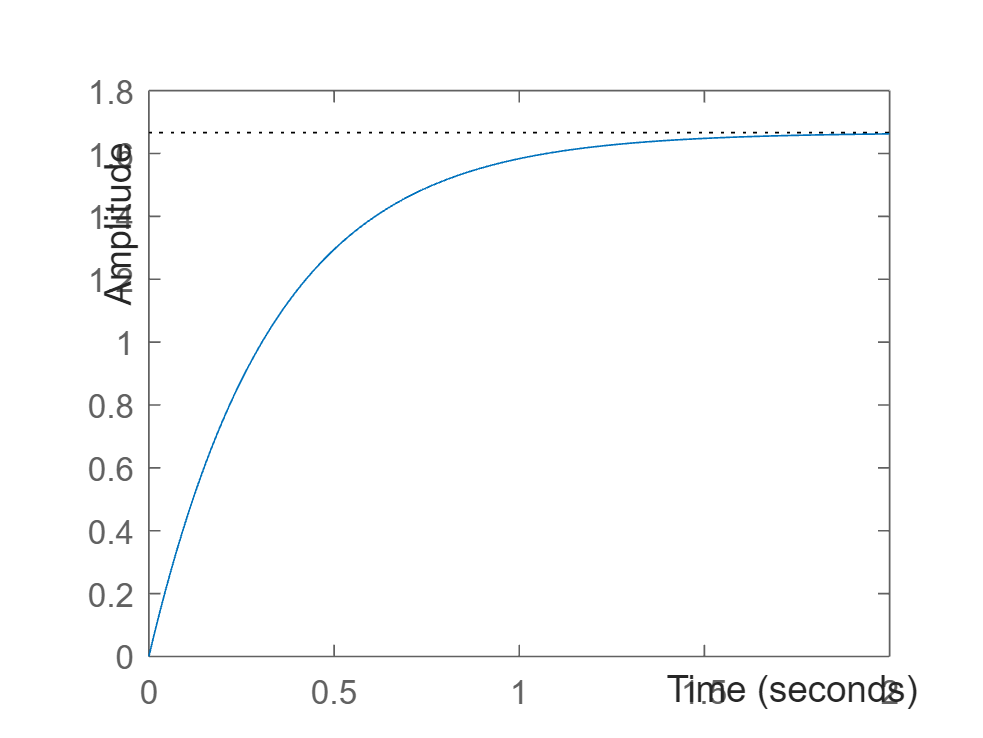

s = tf('s');
G = 5/(s+3); % Definimos la función de transferencia
step(G)      % Obtenemos su respuesta ante entrada escalón unitario

Nótese que esto sería equivalente a solucionar la ecuación diferencial que dio origen a dicha función de transferencia empleando la transformada inversa de Laplace y evaluarla en los instantes de tiempo de interés. Con Matlab:

syms s t
F = (5/(s+3))*1/s;
res = ilaplace(F)

$$res = \frac{5}{3}-\frac{5\,{\mathrm{e}}^{-3\,t}}{3}$$

O lo que es lo mismo, $y\left(t\right)=1\ldotp 6667-1\ldotp 6667e^{-3t}$. Si evaluamos esta función en el mismo rango temporal que la simulación anterior, oh maravilla: obtendremos la misma respuesta:

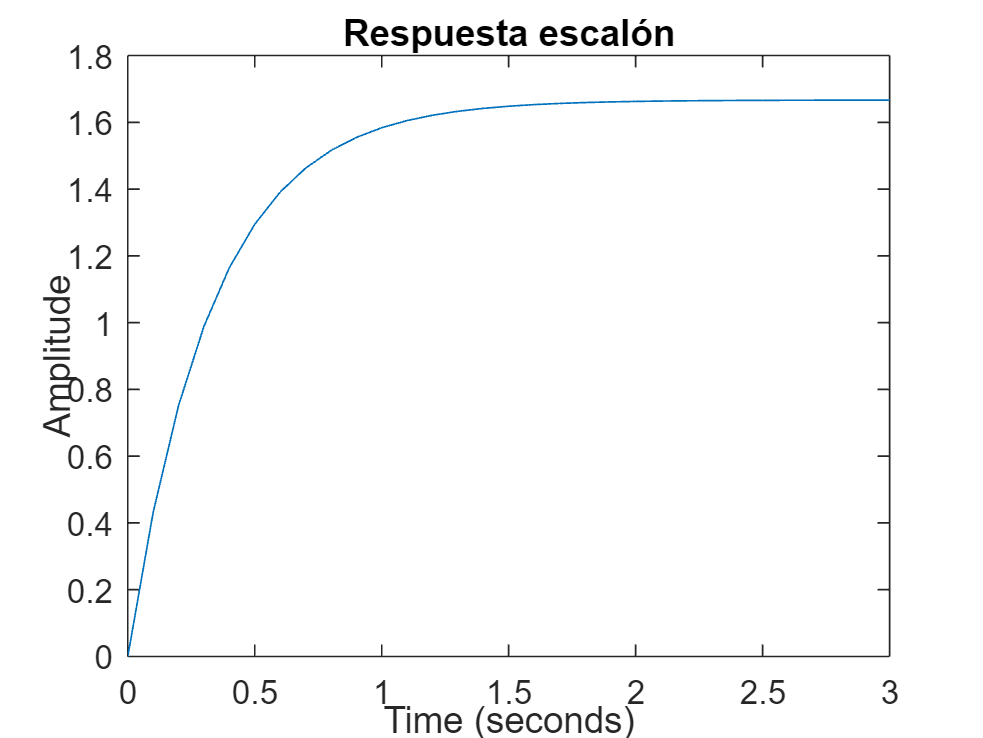

x = 0:0.1:3;
y = zeros(length(x),1);
for i=1:length(x)
    y(i) = subs(res,t,x(i));
end
plot(x,y), title('Respuesta escalón'), xlabel('Time (seconds)'), ylabel('Amplitude')

**Tarea 1:** Analice, de forma cualitativa (estabilidad, ganancia, etc.), cual sería la respuesta esperable, ante una señal de entrada escalón unitario, de los sistemas cuya función de transferencia se indica y verifíquelo empleando el comando `step`.

$G_1 \left(s\right)=\frac{2}{\left(s+2\right)}$ (un polo en el semiplano izquierdo)

% Tu código aquí:
syms s t
G1 = (2/(s+2))*(1/s);
res1 = ilaplace(G1)

$$res1 = 1-{\mathrm{e}}^{-2\,t}$$

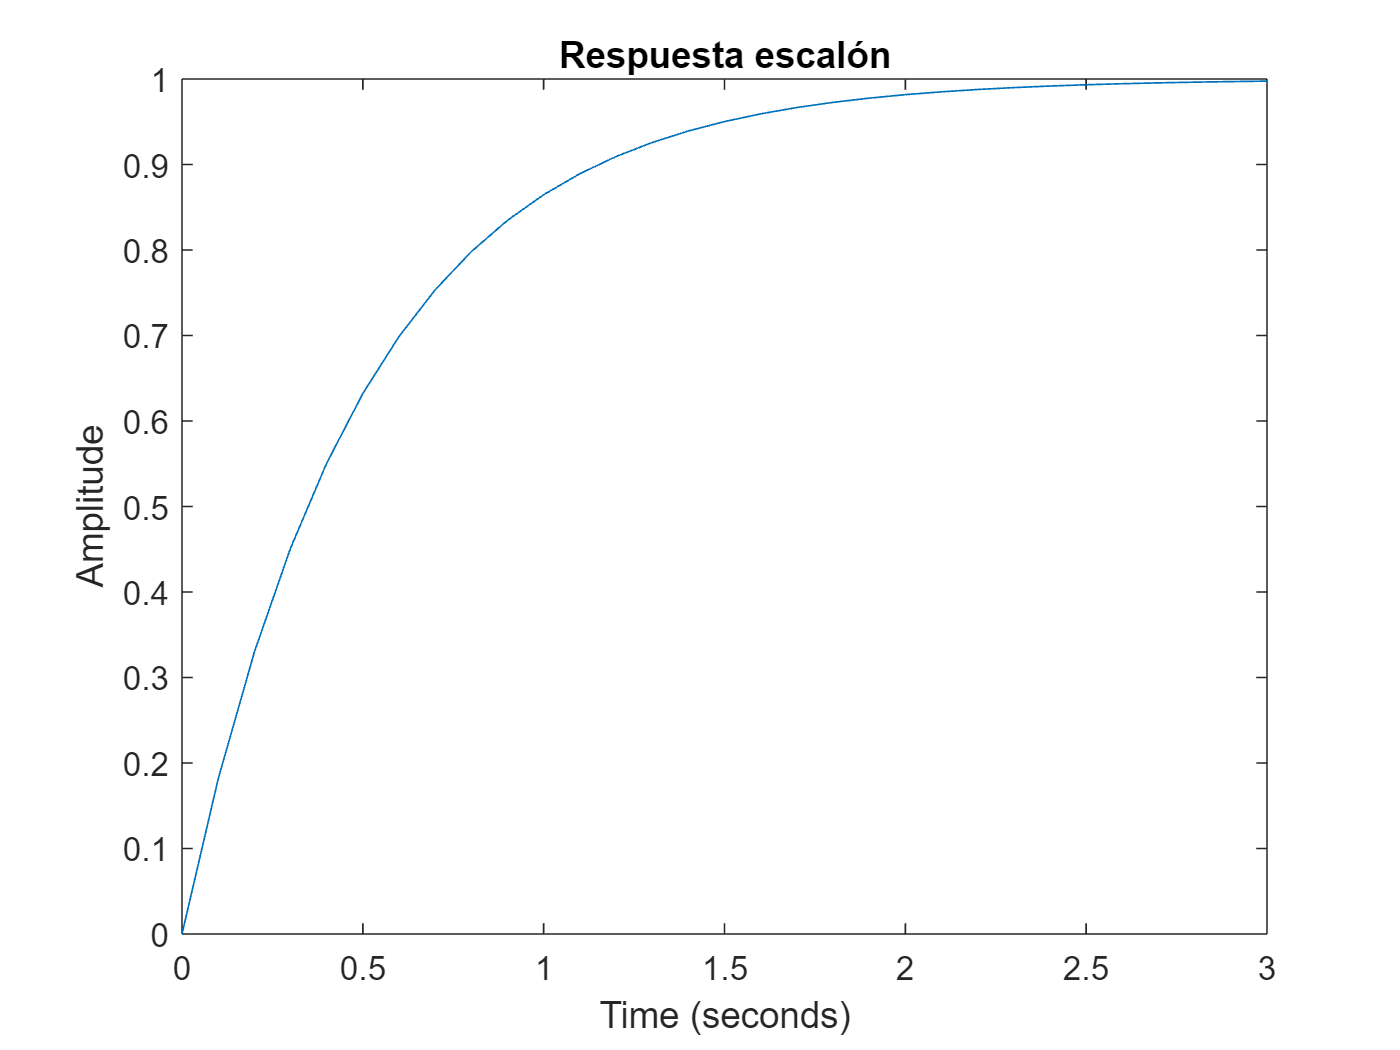

x = 0:0.1:3;
y = zeros(length(x),1);
for i=1:length(x)
    y(i) = subs(res1,t,x(i));
end
plot(x,y), title('Respuesta escalón'), xlabel('Time (seconds)'), ylabel('Amplitude')

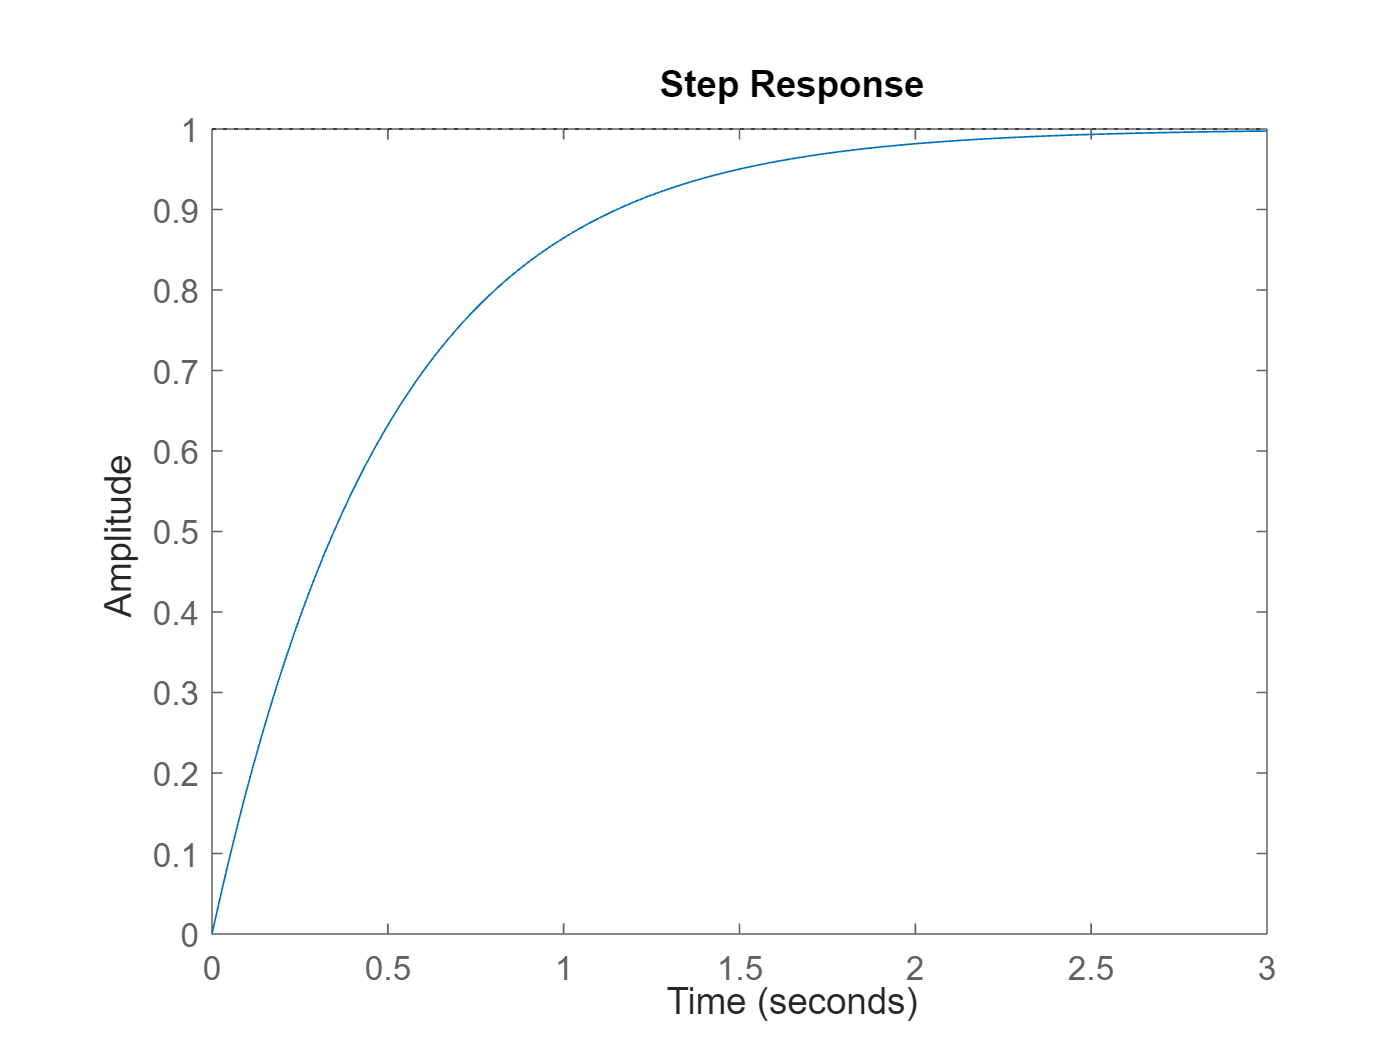

s = tf('s');
G1 = 2/(s+2);
step(G1)

$G_2 \left(s\right)=\frac{3}{\left(s-5\right)}$    (un polo en el semiplano derecho)

% Tu código aquí:
syms s t
G2 = (3/(s-5))*(1/s);
res2 = ilaplace(G2)

$$res2 = \frac{3\,{\mathrm{e}}^{5\,t}}{5}-\frac{3}{5}$$

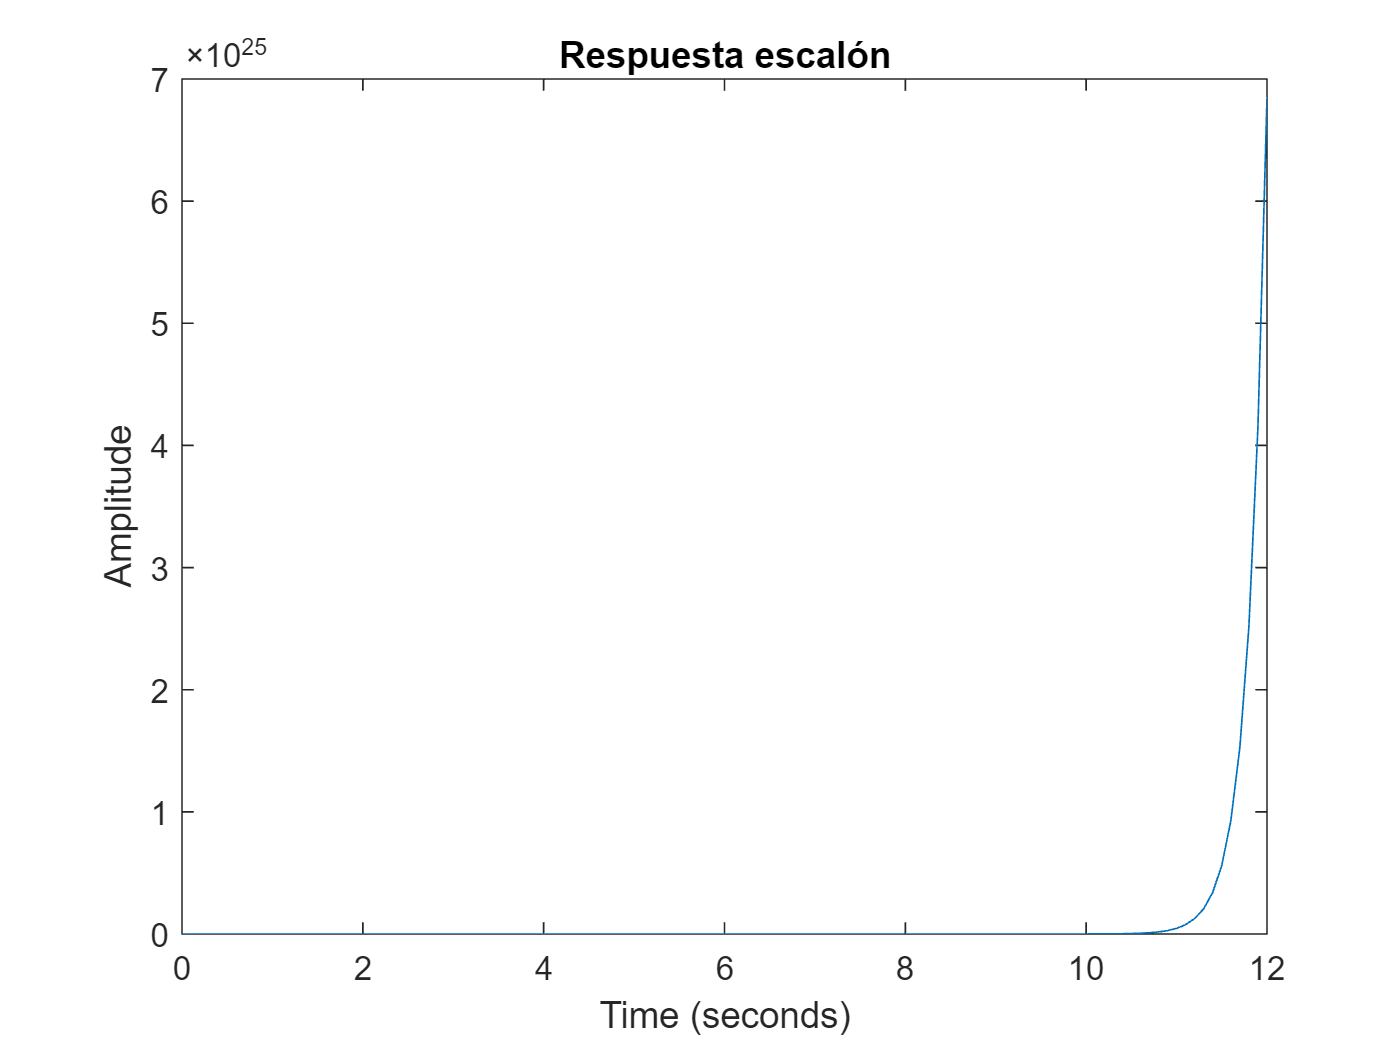

x = 0:0.1:12;
y = zeros(length(x),1);
for i=1:length(x)
    y(i) = subs(res2,t,x(i));
end
plot(x,y), title('Respuesta escalón'), xlabel('Time (seconds)'), ylabel('Amplitude')

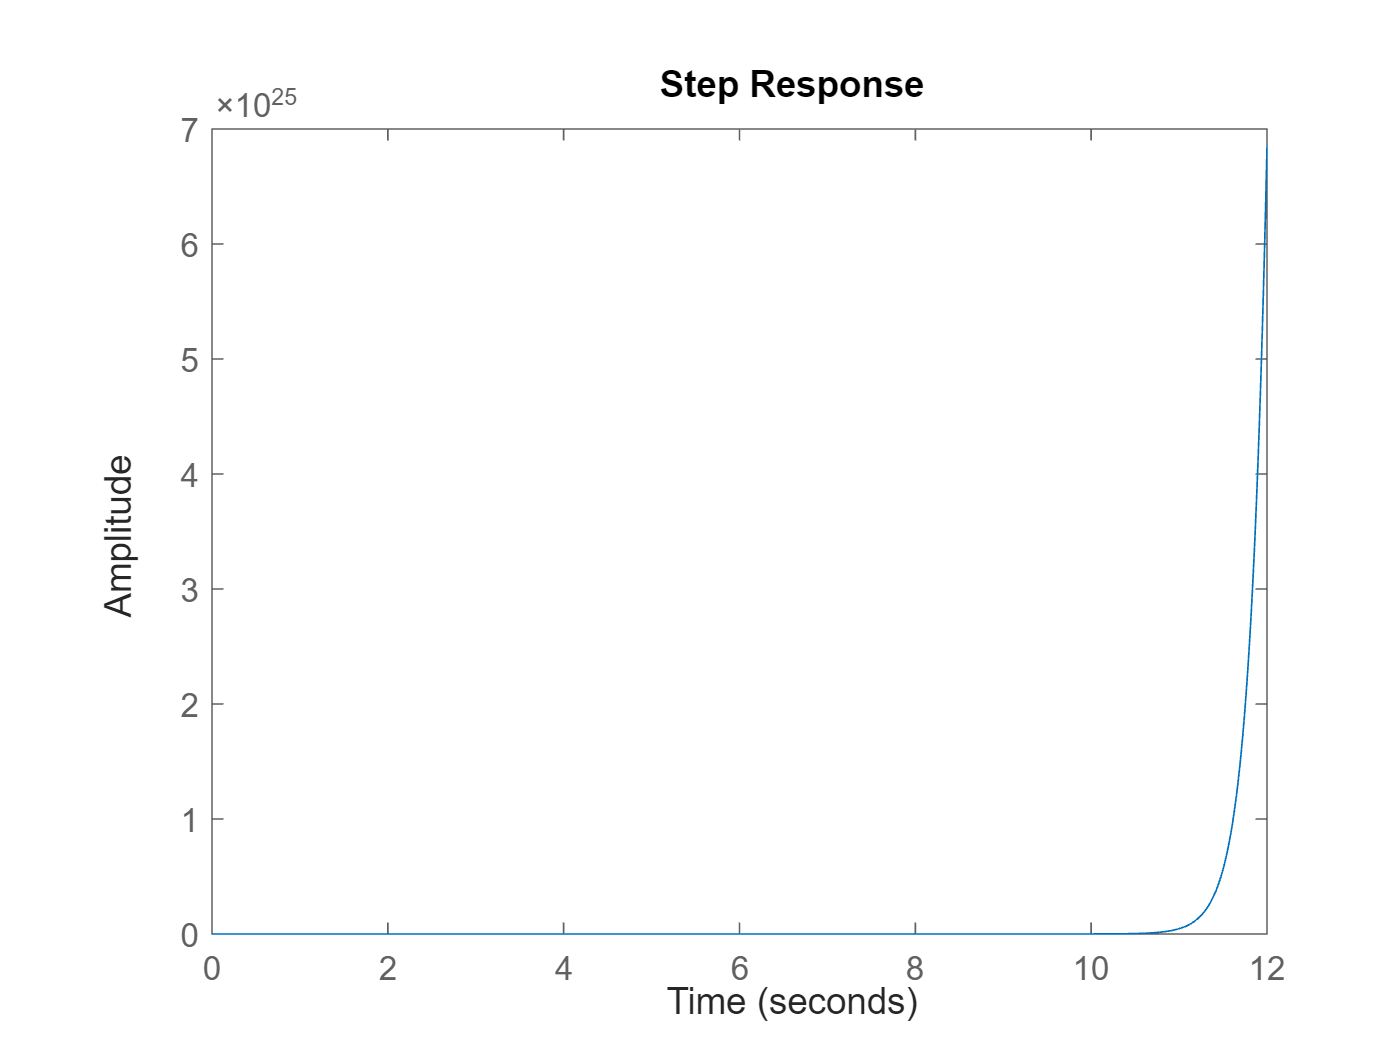

s = tf('s');
G2 = 3/(s-5);
step(G2)

$G_3 \left(s\right)=\frac{1}{\left(s+2\right)\left(s+5\right)}$   (dos polos reales en el semiplano izquierdo)   

% Tu código aquí:
syms s t
G3 = (1/((s+2)*(s+5)))*(1/s);
res3 = ilaplace(G3)

$$res3 = \frac{{\mathrm{e}}^{-5\,t}}{15}-\frac{{\mathrm{e}}^{-2\,t}}{6}+\frac{1}{10}$$

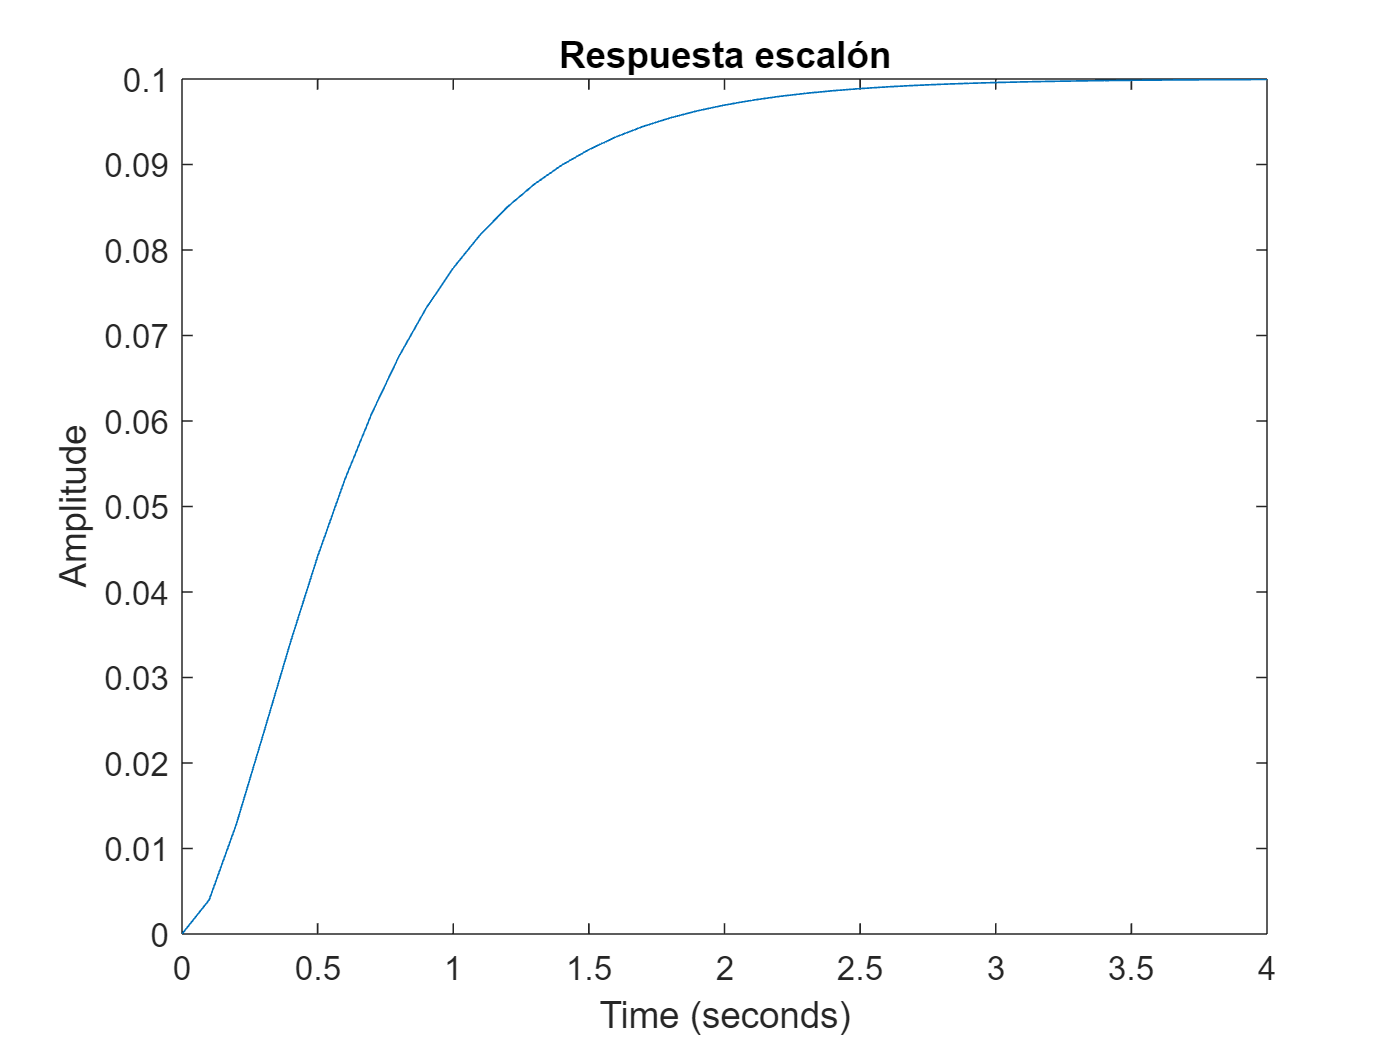

x = 0:0.1:4;
y = zeros(length(x),1);
for i=1:length(x)
    y(i) = subs(res3,t,x(i));
end
plot(x,y), title('Respuesta escalón'), xlabel('Time (seconds)'), ylabel('Amplitude')

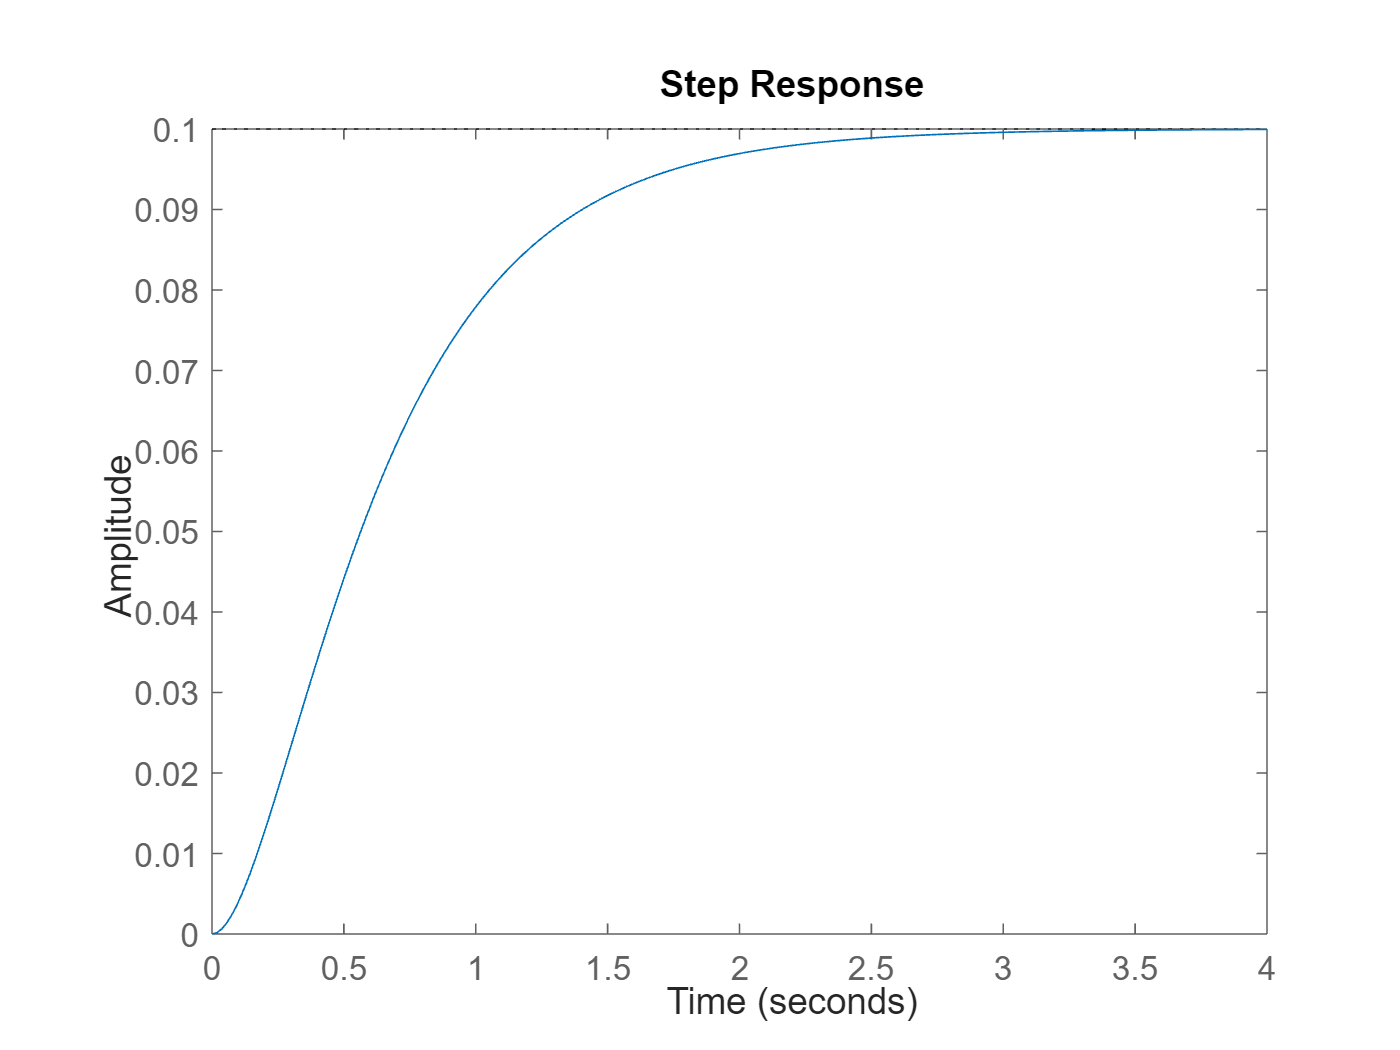

s = tf('s');
G3 = (1/((s+2)*(s+5)));
step(G3)

$G_4 \left(s\right)=\frac{29}{\left(s+2+5j\right)\left(s+2-5j\right)}$   (dos polos complejos en el semiplano izquierdo)

% Tu código aquí:
syms s t
G4 = (29/((s+2+5j)*(s+2-5j)))*(1/s);
res4 = ilaplace(G4)

$$res4 = 1+{\mathrm{e}}^{t\,\left(-2-5\,\mathrm{i}\right)}\,\left(-\frac{1}{2}-\frac{1}{5}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-2+5\,\mathrm{i}\right)}\,\left(-\frac{1}{2}+\frac{1}{5}\,\mathrm{i}\right)$$

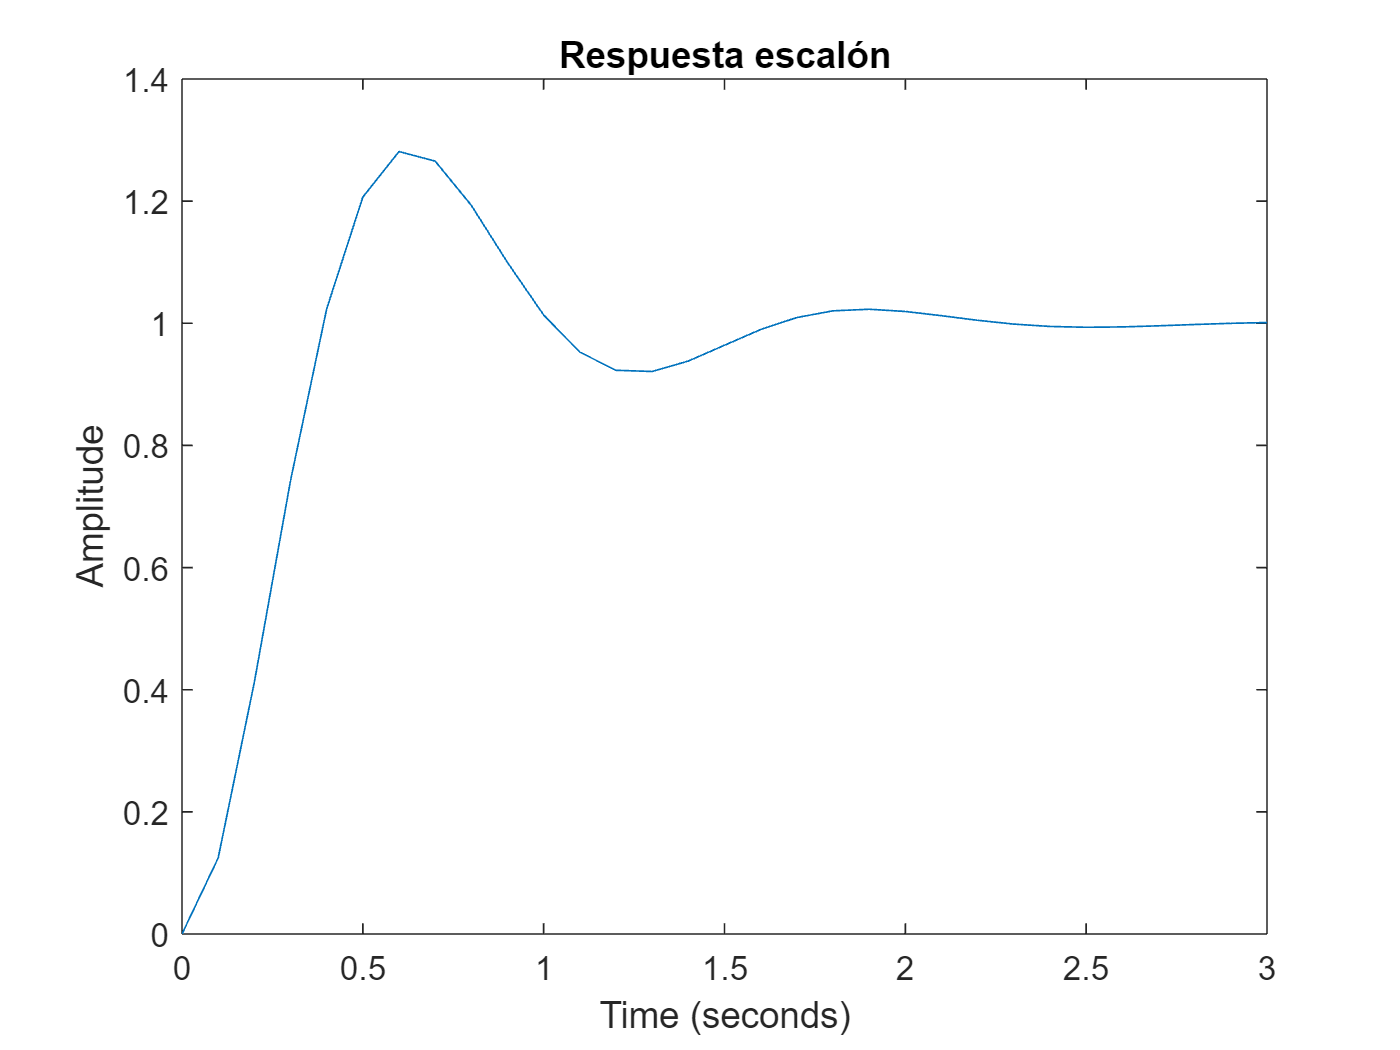

x = 0:0.1:3;
y = zeros(length(x),1);
for i=1:length(x)
    y(i) = subs(res4,t,x(i));
end
plot(x,y), title('Respuesta escalón'), xlabel('Time (seconds)'), ylabel('Amplitude')

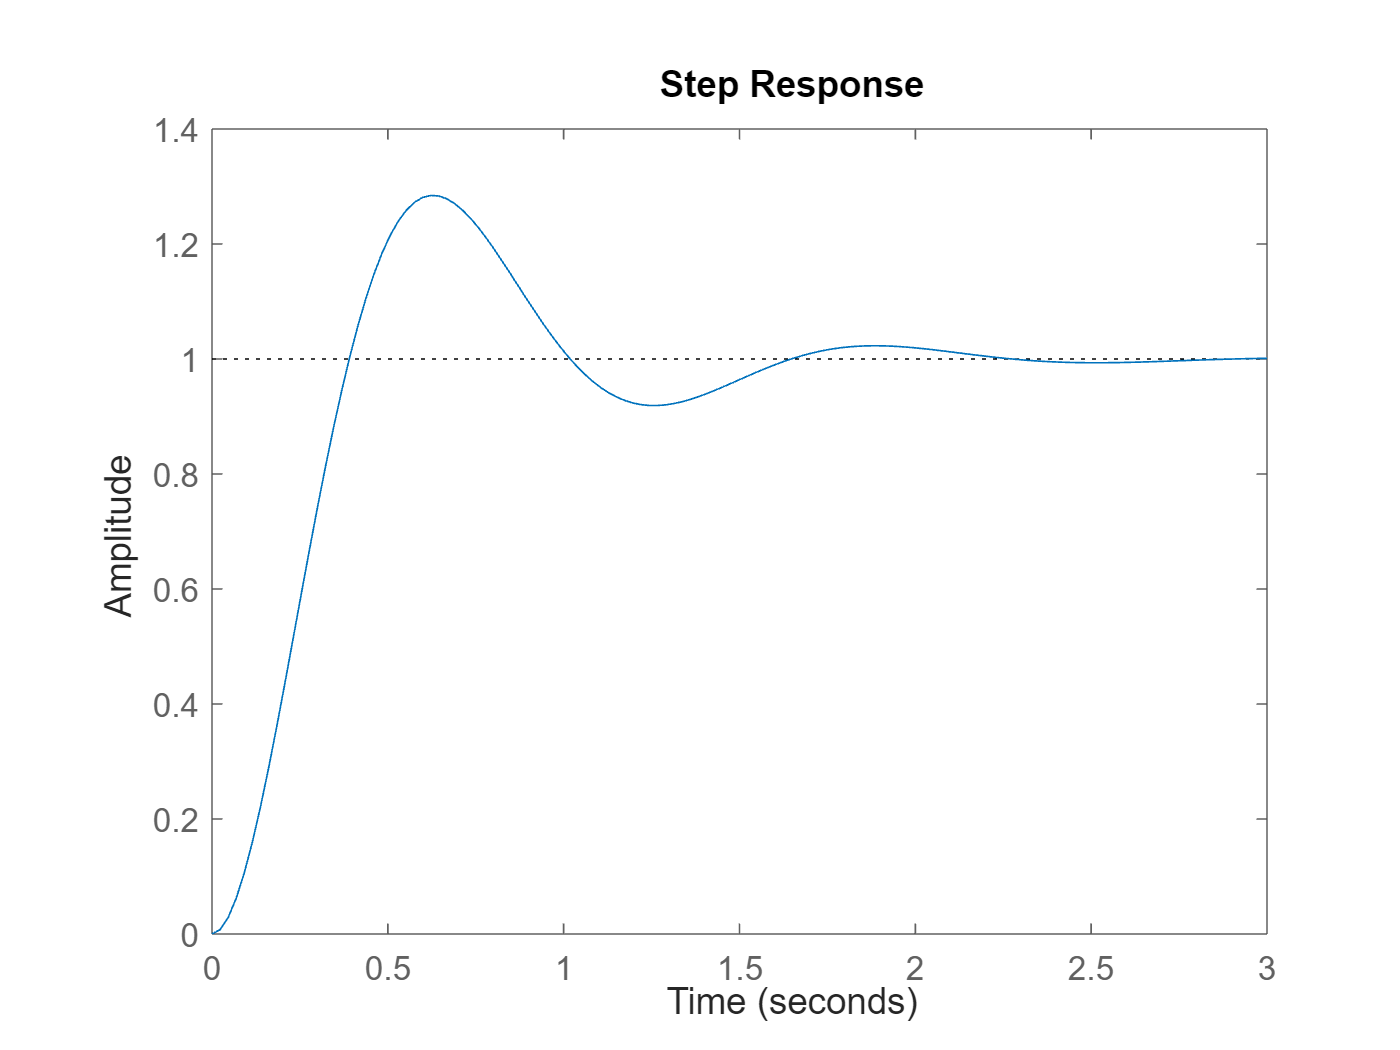


s = tf('s');
G4 = 29/((s+2+5j)*(s+2-5j));
step(G4)


$$G_5 \left(s\right)=\frac{3}{\left(s-1+10j\right)\left(s-1-10j\right)}$$


% Tu código aquí:
syms s t
G5 = (3/((s-1+10j)*(s-1-10j)))*(1/s);
res5 = ilaplace(G5)

$$res5 = \frac{3}{101}+{\mathrm{e}}^{t\,\left(1-10\,\mathrm{i}\right)}\,\left(-\frac{3}{202}+\frac{3}{2020}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(1+10\,\mathrm{i}\right)}\,\left(-\frac{3}{202}-\frac{3}{2020}\,\mathrm{i}\right)$$

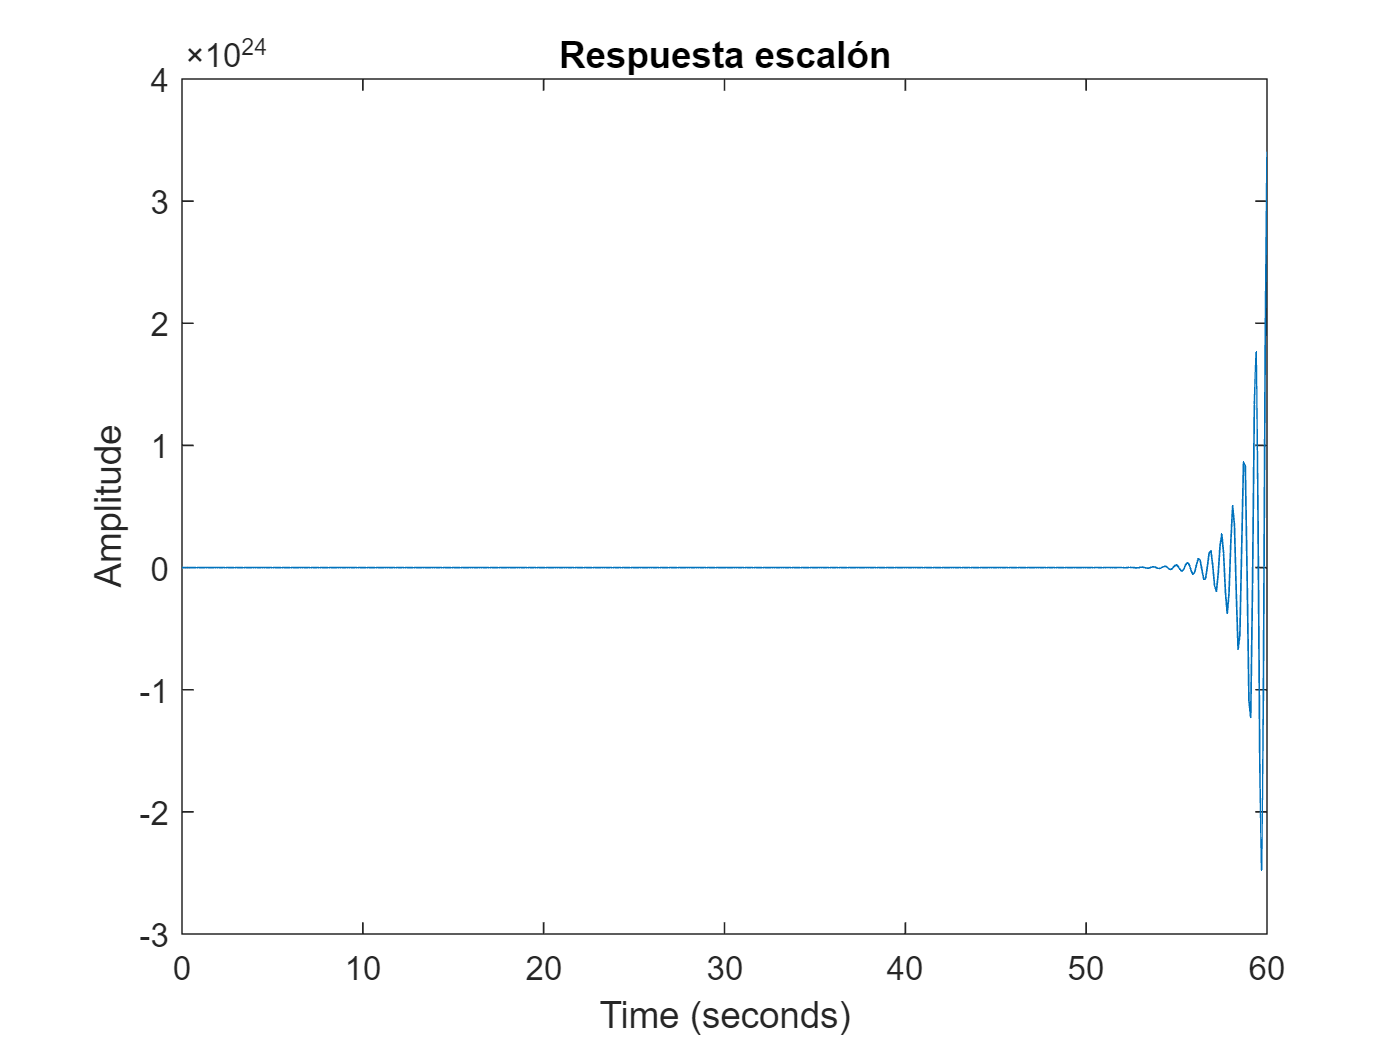

x = 0:0.1:60;
y = zeros(length(x),1);
for i=1:length(x)
    y(i) = subs(res5,t,x(i));
end
plot(x,y), title('Respuesta escalón'), xlabel('Time (seconds)'), ylabel('Amplitude')

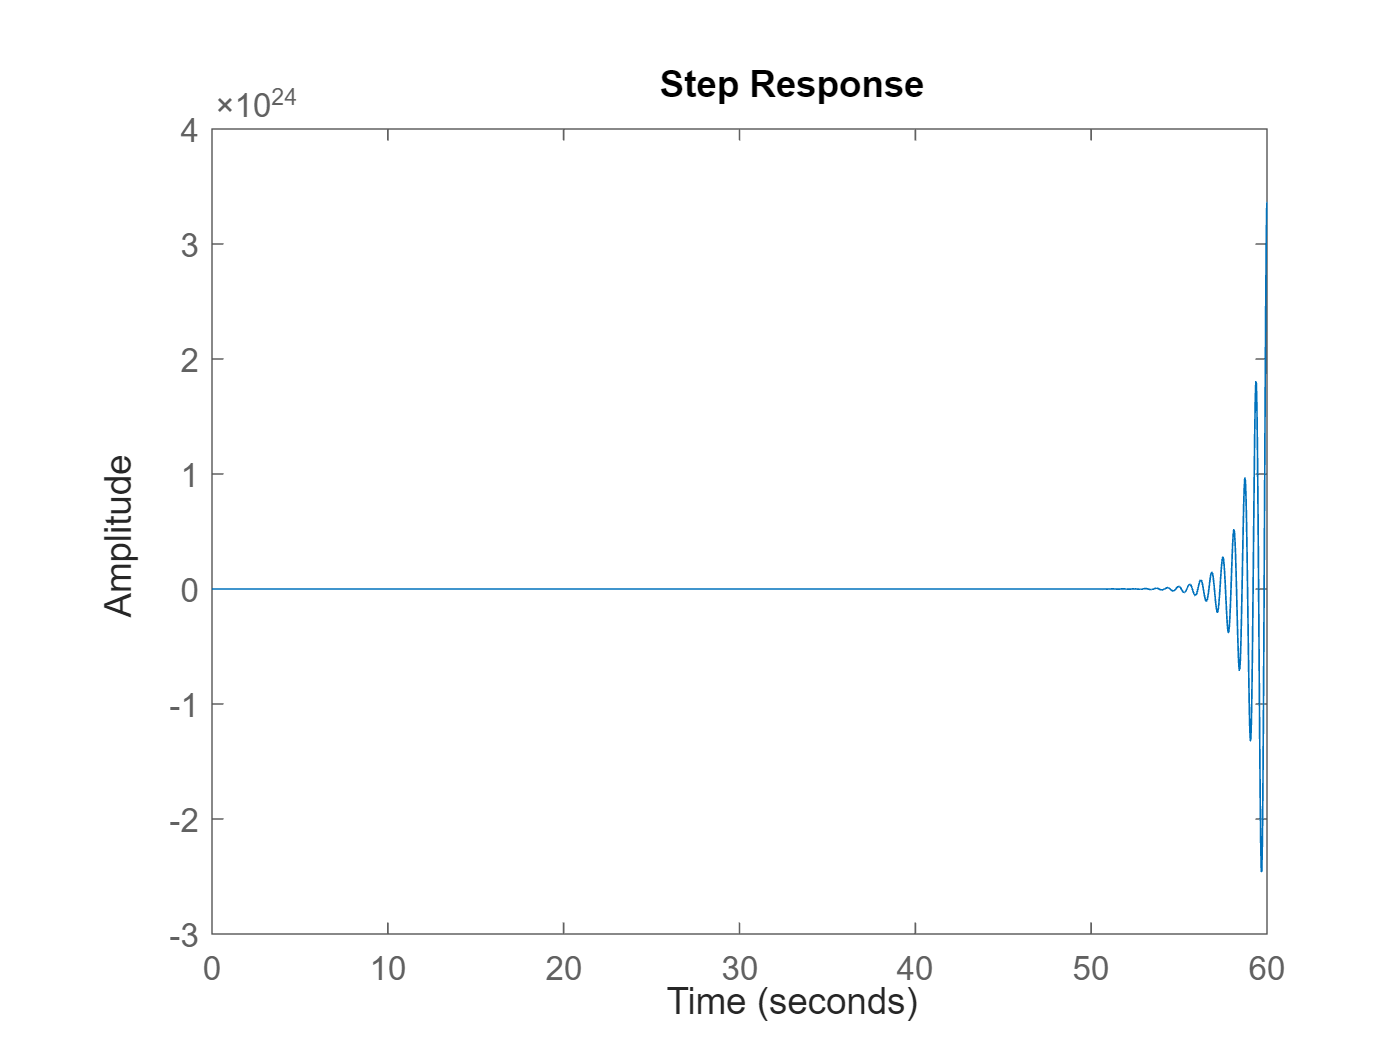


s = tf('s');
G5 = (3/((s-1+10j)*(s-1-10j)));
step(G5)

- `step(sys, tfinal):` Obtiene un resultado análogo al del caso anterior. La respuesta se representará hasta un instante de tiempo igual al valor de tfinal expresado en segundos. Ejemplo:

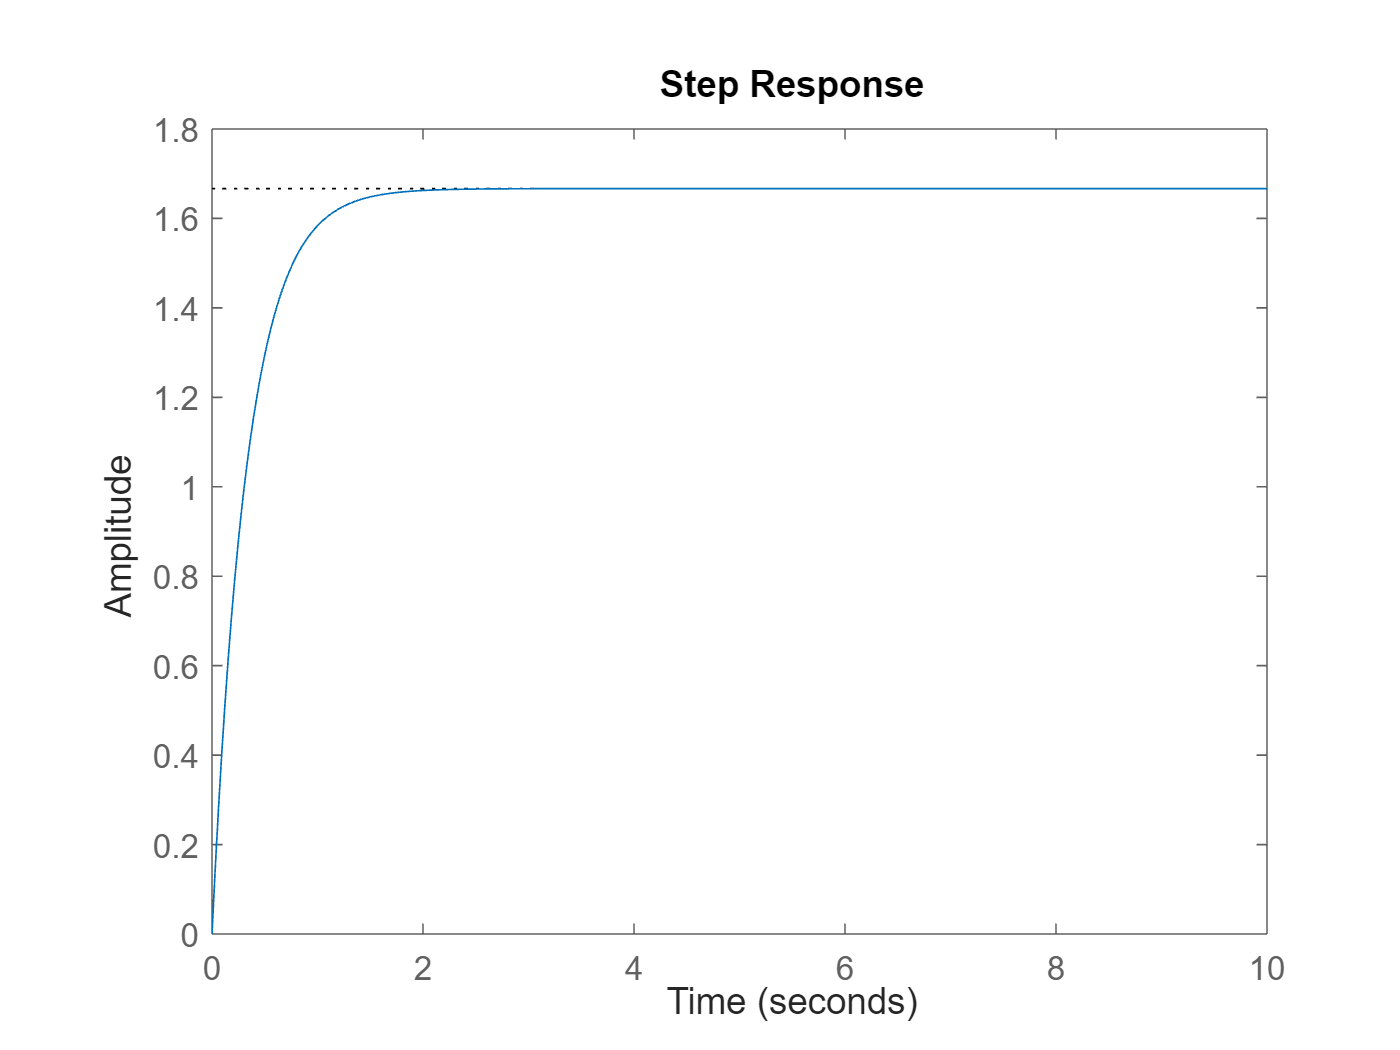

tfinal = 10;   % Definimos el instante de tiempo en el que va a finalizar la visualización de la respuesta
step(G,tfinal) % Obtenemos su respuesta ante entrada escalón unitario hasta tfinal

- `step(sys, t):` Obtiene un resultado análogo al de los casos anteriores. La respuesta se representará para un vector de tiempos dado por el valor de `t`. Éste debe ser un vector de elementos igualmente espaciados (`dt` segundos), de la forma:` t = 0:dt:tfinal`. En cualquier caso, dicha separación `dt` deberá ser escogida de forma que la respuesta transitoria sea visible con suficiente detalle. Ejemplo:

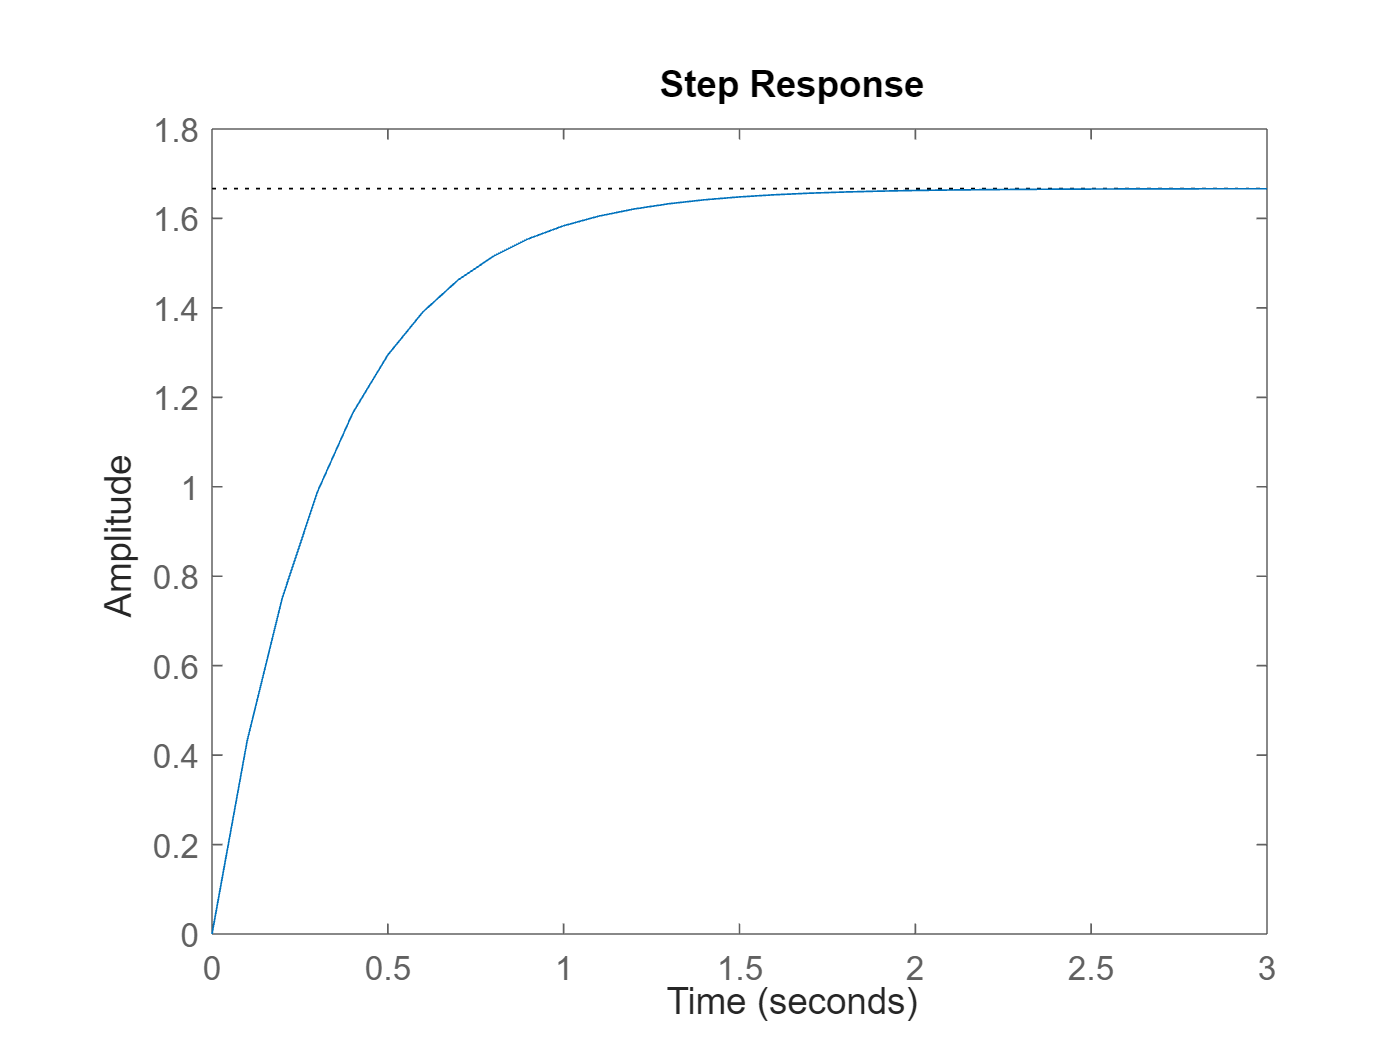

t = 0:0.1:3;  % Definimos el vector de elementos igualmente espaciados cada 0.1s
step(G,t)     % Obtenemos la respuesta escalón en dichos instantes de tiempo

Ejemplo con un `dt` demasiado grande:

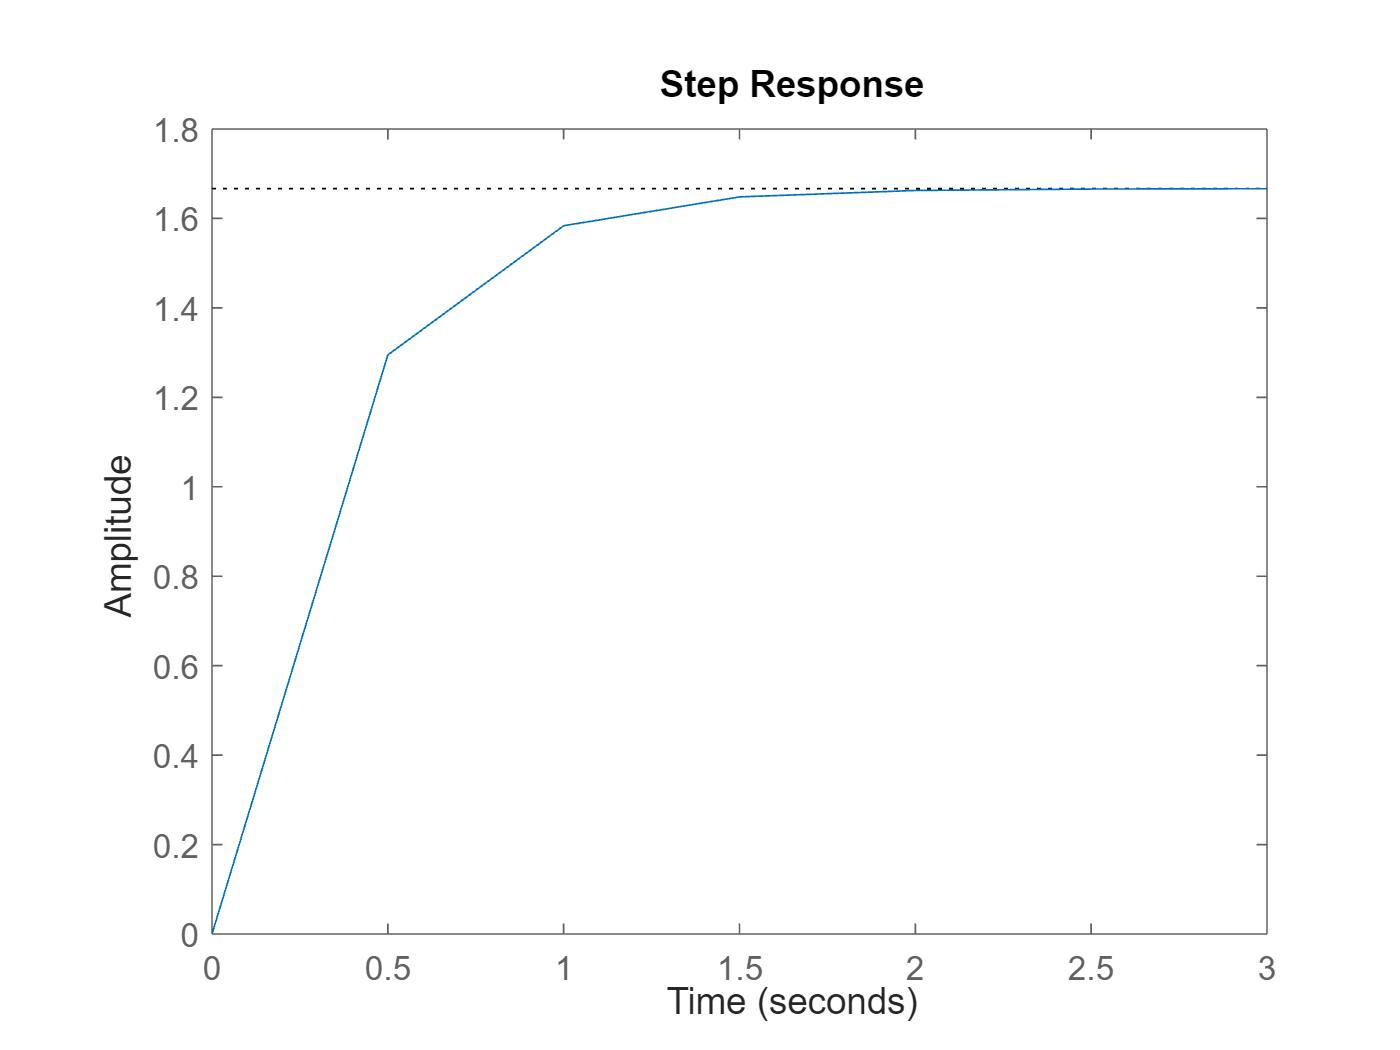

t = 0:0.5:3;  % Definimos el vector de elementos igualmente espaciados cada 0.5s
step(G,t)     % Obtenemos la respuesta escalón en dichos instantes de tiempo

### `1.1 Simulación simultánea de varios sistemas`

MATLAB  permite mostrar la respuesta de varios sistemas ante la misma entrada en un mismo gráfico. Para ello se puede usar el comando `step` con la siguiente sintáxis:

- `step(sys1, sys2, sys3, …):` Obtiene en una nueva ventana la representación gráfica de las respuestas que presentarían, ante la aplicación de una señal de entrada escalón unitario, los sistemas cuyos modelos matemáticos fuesen los almacenados en las variables `sys1`,`sys2`, `sys3`, etc. Esta forma de llamada a la función `step` es útil para comparar respuestas de múltiples sistemas. Ejemplo:

Gbis = 3/(s+2); % Definimos el modelo de un segundo sistema
step(G,Gbis) % Mostramos la respuesta escalón de ambos

Error using DynamicSystem/step
In time response commands, the final time must be a positive scalar.

legend


**Tarea 2:** Para el sistema cuya función de transferencia es $G_4 \left(s\right)$, indicar qué influencia tendría, en su respuesta temporal ante una señal de entrada escalón unitario, el añadido de un polo real situado en el semiplano izquierdo complejo. ¿Cómo afectaría la ubicación de dicho polo con respecto a la que tienen los polos de la función de transferencia original? Obtenga y compare las respuestas que presentaría ante una señal de entrada escalón unitario dicho sistema, con y sin el polo añadido, si éste es ubicado en -1, -3 y -20 (para ello deberá superponer las gráficas de ambas respuestas, empleando, si es preciso a efectos de comparación, una ganancia que asegure que las mismas se estabilicen en 1).

*Respuesta a la pregunta aquí: *

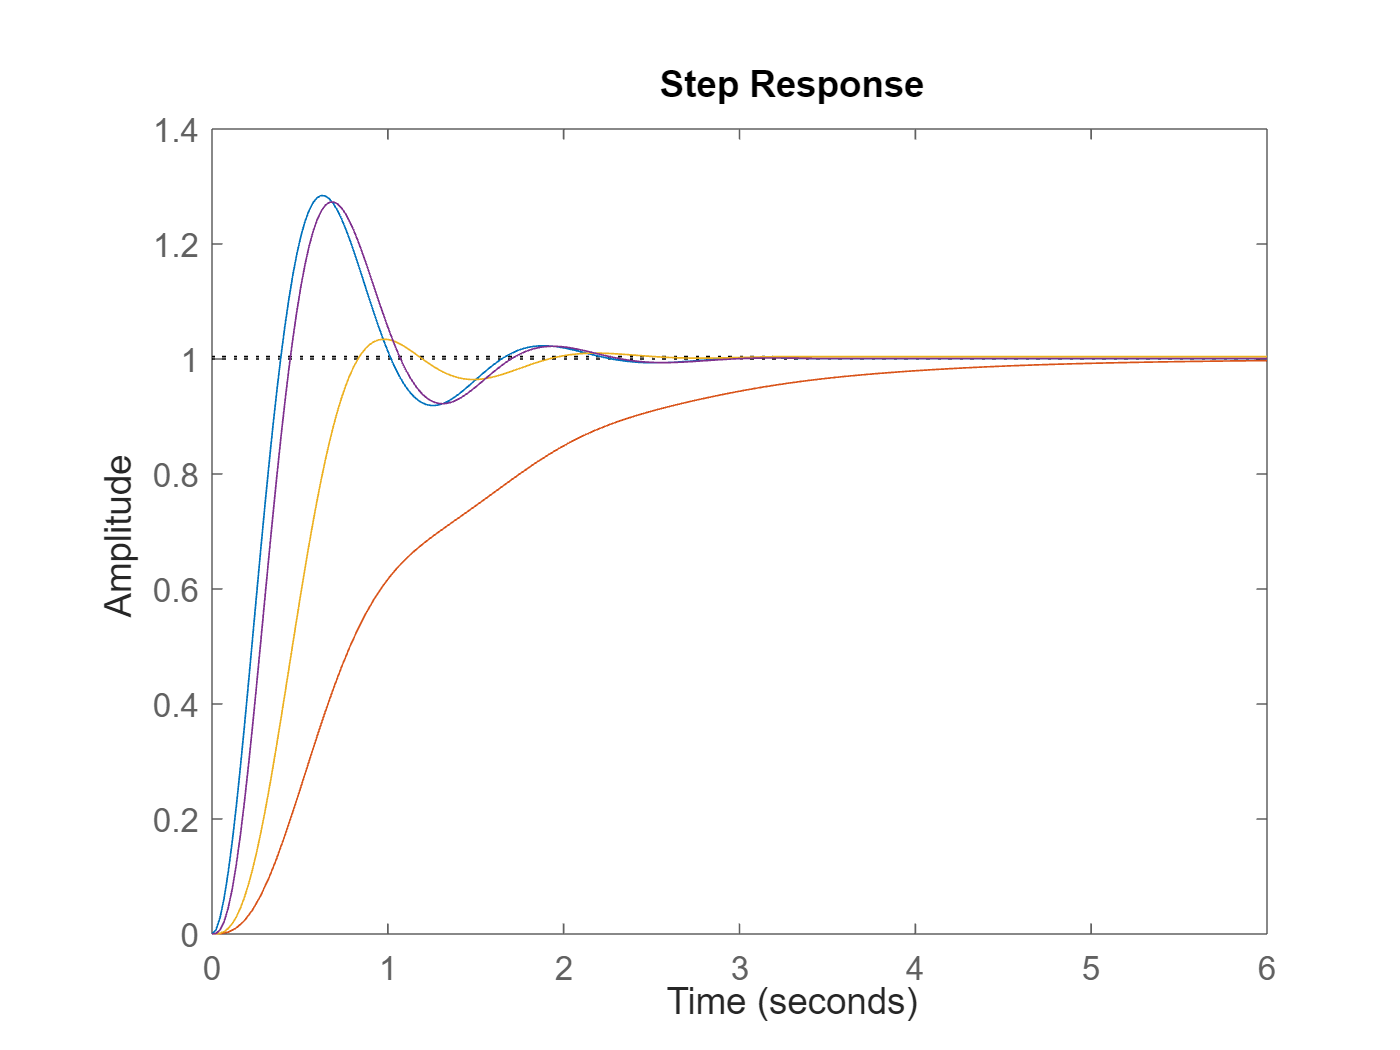

% Tu código aquí
s = tf('s');
G4 = 29/((s+2+5j)*(s+2-5j));
G4_1 = (29/((s+2+5j)*(s+2-5j)))*(1/(s+1));
G4_3 = (29/((s+2+5j)*(s+2-5j)))*(1/(s+3));
G4_20 = (29/((s+2+5j)*(s+2-5j)))*(1/(s+20));
step(G4,(G4_1),(G4_3/0.332),(G4_20/0.05))

`Resultado esperado: `

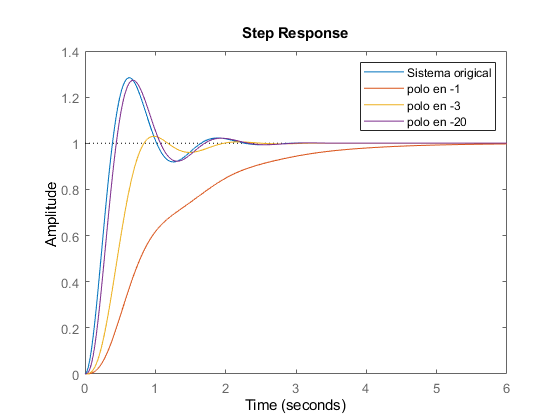

**Tarea 3:** Para el sistema cuya función de transferencia es $G_{\;4} \left(s\right)$, indicar qué influencia tendría, en su respuesta temporal ante una señal de entrada escalón unitario, el añadido de un cero real situado en el semiplano izquierdo complejo. ¿Cómo afectaría la ubicación de dicho cero con respecto a la que tienen los polos de la función de transferencia original? Obtenga y compare las respuestas que presentaría ante una señal de entrada escalón unitario dicho sistema, con y sin el cero añadido, si éste es ubicado en -1, -3 y -20 (superponer las correspondientes gráficas conforme a lo indicado en el ejercicio anterior). 

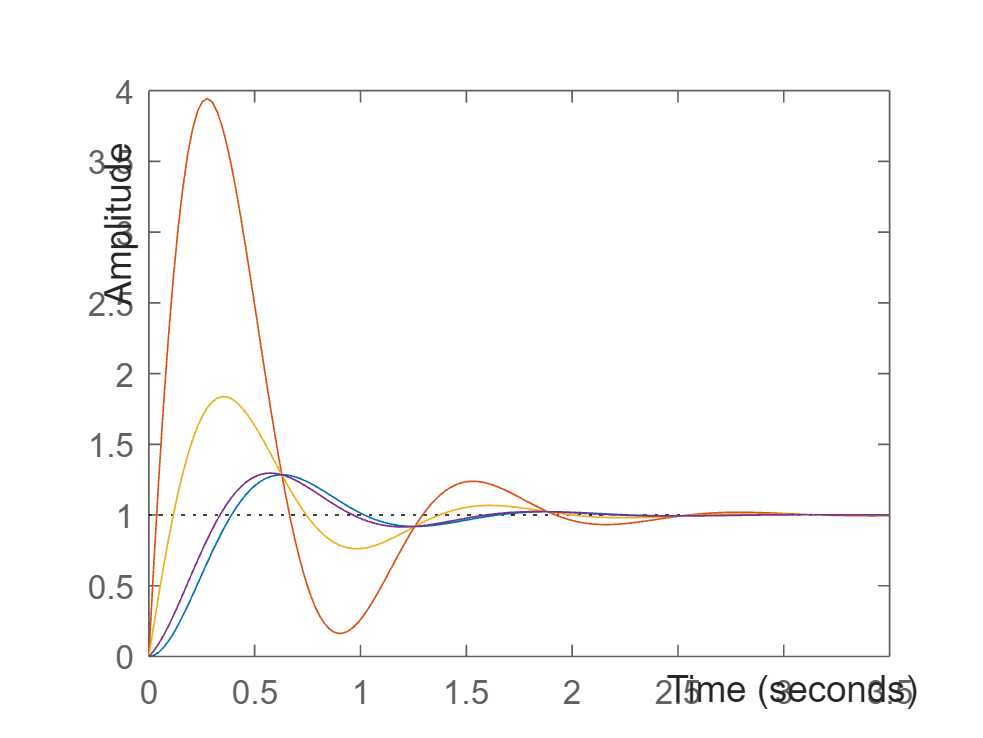

% Tu código aquí
G4=zpk([],[-2+5*i -2-5*i],29);
G4_1=zpk(-1,[-2+5*i -2-5*i],29);
G4_3=zpk(-3,[-2+5*i -2-5*i],29/3);
G4_20=zpk(-20,[-2+5*i -2-5*i],29/20);
step(G4,G4_1,G4_3,G4_20)

`Resultado esperado: `

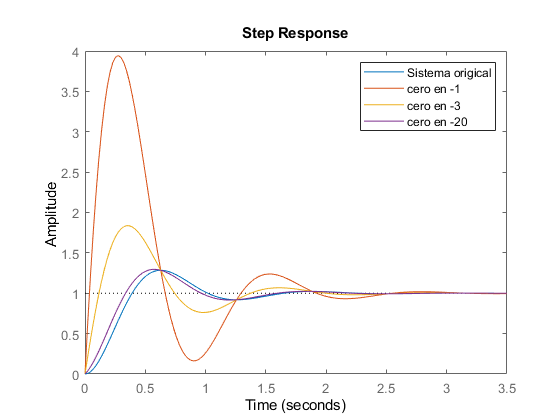

**Tarea 4:** La función de transferencia $G_6 \left(s\right)$ dada representa el modelo de una planta que es regulada, en bucle cerrado y con realimentación negativa y unitaria, mediante un controlador cuya función de transferencia, $G_c \left(s\right)$, es igualmente dada. Obtenga la respuesta temporal que este sistema realimentado presentaría ante una señal de entrada escalón unitario para los siguientes valores de la ganancia K indicada en el modelo del controlador: `K = 1`, `K = 4`, `K = 8.4` y `K = 15`. ¿Qué conclusiones pueden alcanzarse a partir de los resultados obtenidos?

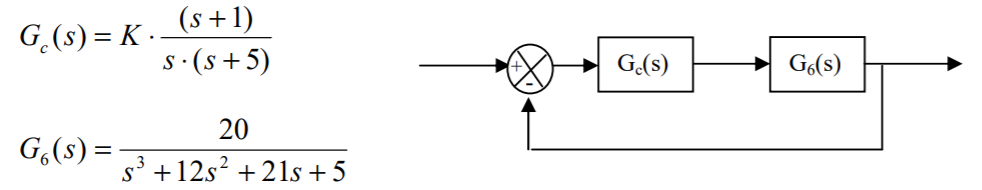

Pista: Muestra los resultados para `K=1` y `K=4` en una gráfica, y para` K=8.4` y `K=15` en otra distinta.

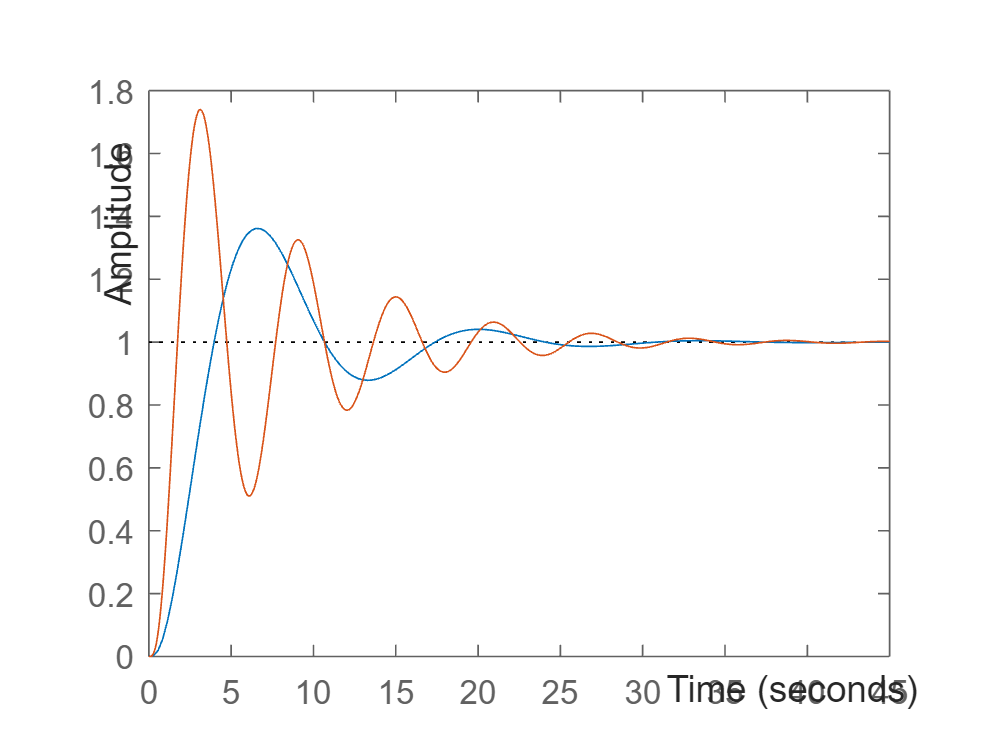

% Tu código aquí
s=tf('s');
Gc=(s+1)/(s*(s+5));
G6=20/(s^3+12*s^2+21*s+5);
S1=feedback(series(G_c,G_6),1);
S2=feedback(series(4*G_c,G_6),1);
S3=feedback(series(8.4*G_c,G_6),1);
S4=feedback(series(15*G_c,G_6),1);
step(S1,S2)

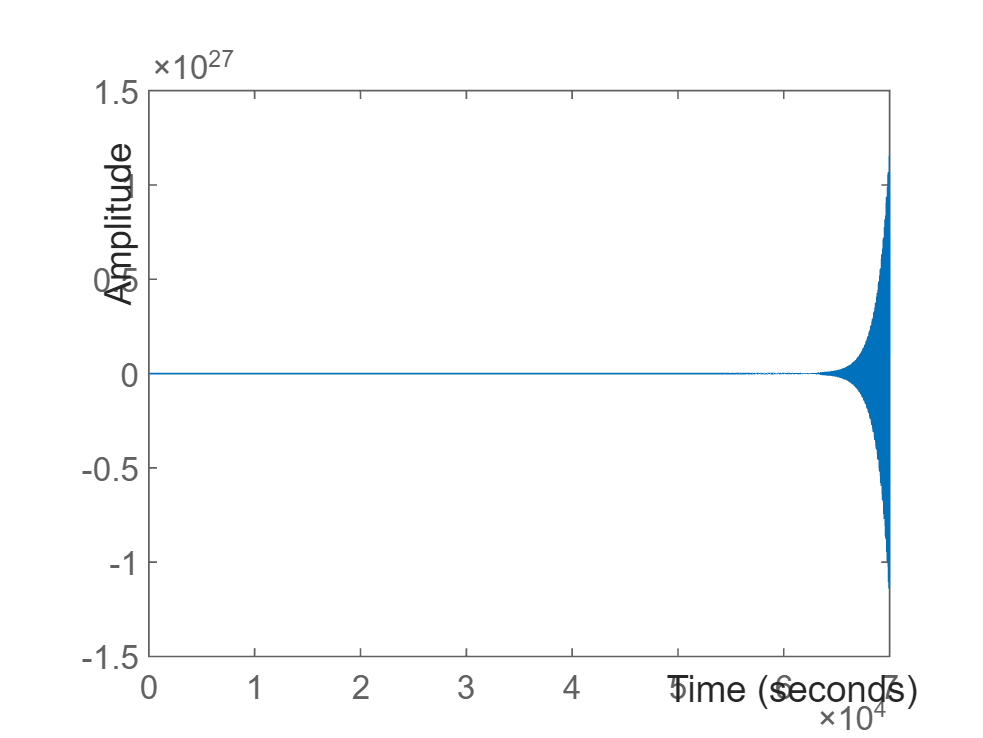

step(S3)

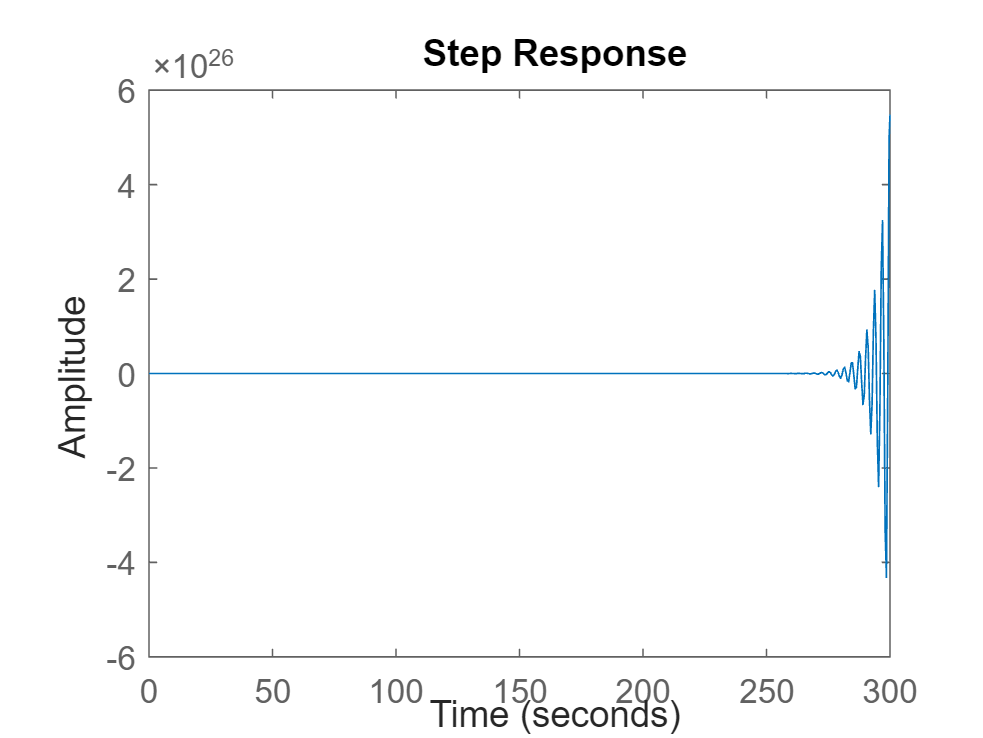

step(S4)

`Resultado esperado:`

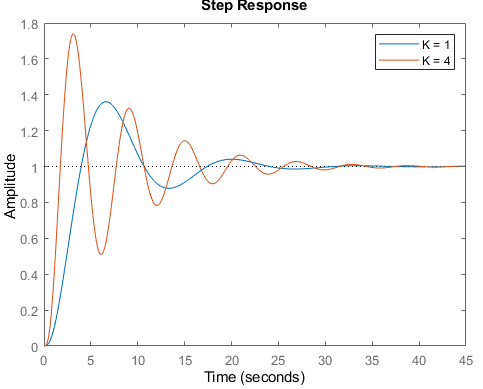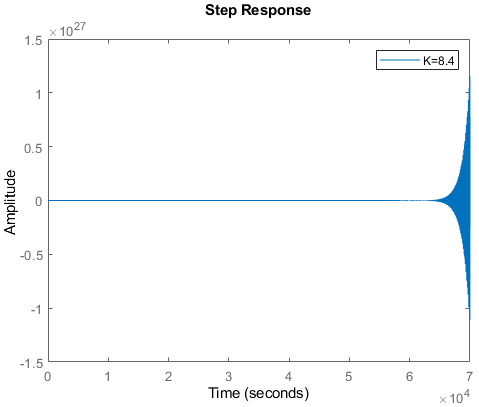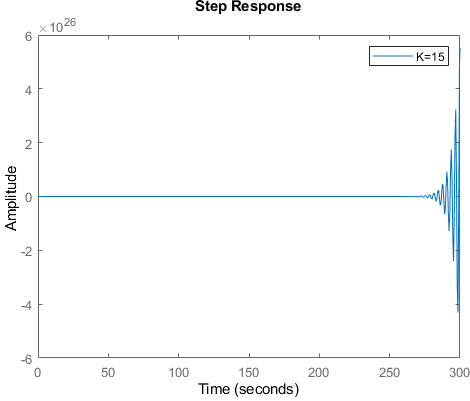

- `step(sys1, ‘f1’, sys2, ‘f2’, … ):` Obtiene un resultado análogo al del caso anterior. Las respuestas se representarán con los formatos indicados por ‘fi’, según los criterios aplicados en la función plot. Así, por ejemplo, `‘g--’ `determinaría que la respuesta correspondiente se representaría con una línea discontinua de color verde. Ejemplo:

step(G,'b.',Gbis,'m--')     % Mostramos la respuesta escalón de ambos con distinto formato

Unrecognized function or variable 'Gbis'.

legend

### `1.2 Jugando con el gráfico `

En todos los casos anteriores es posible activar uno o más cursores sobre las diferentes gráficas representadas. Para ello bastaría con pulsar el botón izquierdo del ratón cuando el cursor esté situado sobre la gráfica en cuestión. Junto a cada cursor se indicará: la variable que almacena el modelo del sistema para el que se ha obtenido la respuesta temporal considerada y el instante de tiempo y el valor de la salida asociados a la posición del cursor. Ejemplo:

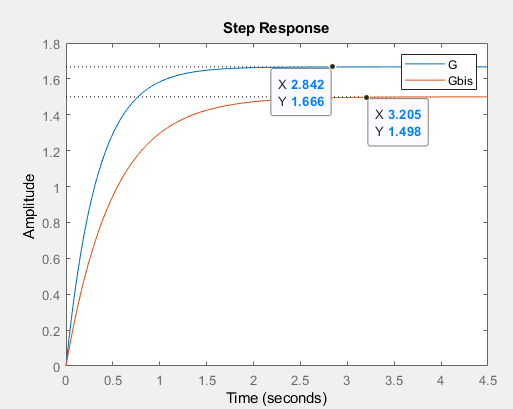

Asimismo, y aunque estudiaremos estos conceptos más adelante, en todos los casos anteriores es posible determinar los valores de ciertas características de las respuestas representadas. En concreto, se puede determinar:

- el pico de la respuesta (máximo sobreimpulso, sobreoscilación y tiempo de pico), 

- el tiempo de establecimiento, 

- el tiempo de subida, y 

- el valor de estabilización. 

Para ello bastaría con pulsar el botón derecho del ratón cuando el cursor esté situado en el interior de la correspondiente ventana, seleccionar la opción *Characteristics* en el menú mostrado y elegir la característica a mostrar [peak response (peak amplitude, overshoot y peak time), settling time, rise time y steady state, respectivamente]. Como consecuencia de ello, aparecerá resaltado sobre cada respuesta representada un punto vinculado con dicha característica y pulsando el botón izquierdo del ratón cuando el cursor se encuentre sobre dicho punto se mostrará junto a él el nombre de la variable que almacena el modelo del sistema asociado a la respuesta en cuestión y el nombre y valor de la característica. Ejemplo:

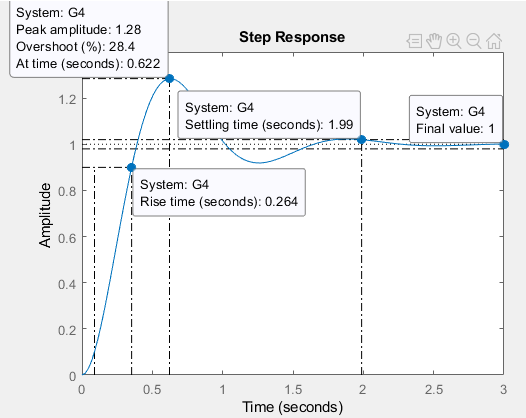

Por otra parte, en todos aquellos casos en los que en una misma gráfica se hayan representado las respuestas de dos o más sistemas; es posible ocultarlas/mostrarlas pulsando el botón derecho del ratón, seleccionando la opción *Systems* en el menú mostrado y seleccionando el nombre de la variable que almacena el modelo del sistema cuya respuesta se desea ocultar/mostrar.  

Si se desea, es posible visualizar y ocultar una rejilla en la ventana en la que se realizan las representaciones gráficas de las respuestas. Para ello, bastará con pulsar el botón derecho del ratón y seleccionar la opción *Grid* en el menú mostrado. 

Finalmente, es posible modificar algunas propiedades de las gráficas representadas. Entre ellas cabe citar: 

- las etiquetas (*labels*) que acompañan a los ejes y a la ventana gráfica, 

- los valores límites (*limits*) de la salida y el tiempo considerados en los ejes, y 

- determinadas opciones (*options*) asociadas a las características de las respuestas, en concreto, el criterio utilizado para la determinación del tiempo de establecimiento (por defecto es el del 2%) y del tiempo de subida (por defecto es el del 10 al 90%). 

Para ello, bastará con pulsar el botón derecho del ratón, seleccionar la opción *Properties*, pinchar, en la ventana de diálogo mostrada a continuación, sobre la pestaña (etiquetada como *labels*, *limits* u *options*) asociada a la propiedad que se desee modificar y realizar el correspondiente cambio. Ejemplo:

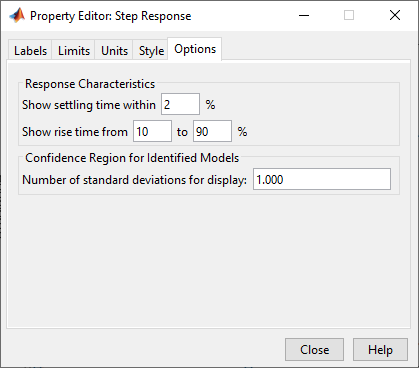

### `1.3 Guardando la salida de la respuesta`

El comando `step` puede ejecutarse de tal manera que podamos guardar en variables de MATLAB resultados interesantes sobre su ejecución. Por ejemplo:

- `[y, t] = step(sys):` Obtiene dos vectores representativos de la respuesta que presentaría, ante la aplicación de una señal de entrada escalón unitario, un sistema cuyo modelo matemático fuese el almacenado en la variable `sys`. En este caso no se obtiene ninguna representación gráfica. `y` es el vector o la matriz de los valores de la/s señal/es de respuesta. `t` es el vector de tiempos. Para sistemas con una sola entrada, `y` tiene igual número de filas que el vector `t` y tantas columnas como señales de salida. Para sistemas con múltiples entradas, `y` proporciona las respuestas a un escalón para cada canal de entrada, las cuales son diferenciables por medio de una tercera dimensión. Así, y`(:,:,j)` proporciona la respuesta a un escalón correspondiente al canal de entrada jésimo. 

- `y = step(sys, t):` Obtiene un resultado análogo al del caso anterior. La respuesta se generará para un vector de tiempos dado por el valor de `t`, cuyo formato ha de ser idéntico al descrito más arriba. 

El almacenar la respuesta en una variable puede ser intersante para analizarla en detalle, como veremos a lo largo del curso. Además, la respuesta podría visualizarse posteriormente utilizando el comando `plot`. Por ejemplo:

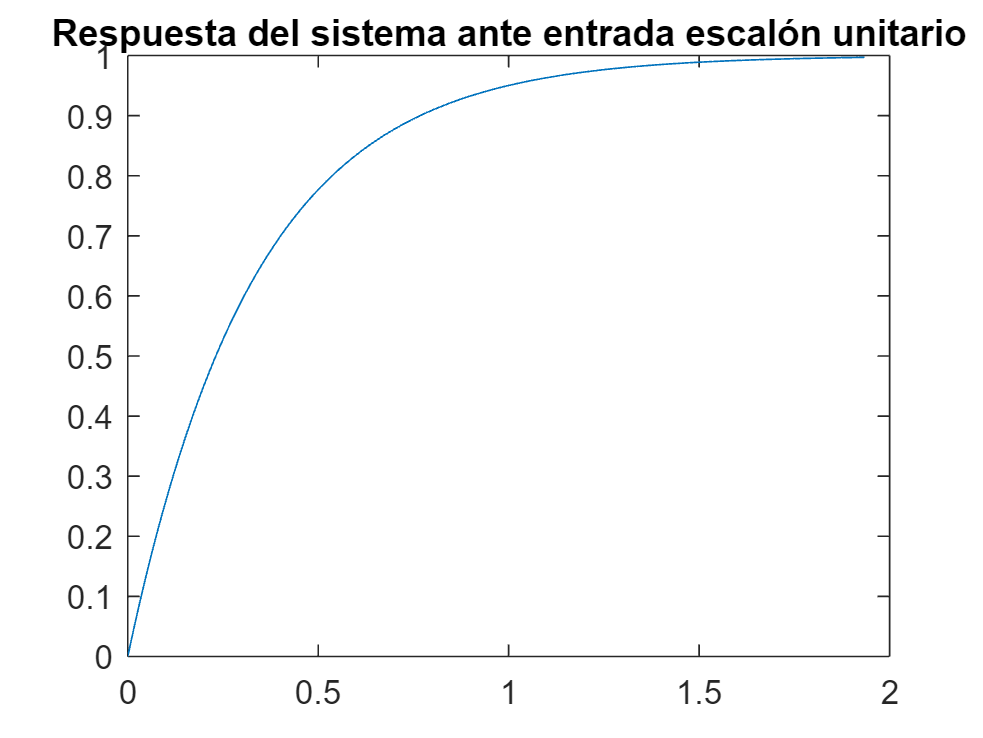

G = tf(3,[1 3]);
[y,t] = step(G);
plot(t,y), title('Respuesta del sistema ante entrada escalón unitario')

### `1.4 Escalones de distinta amplitud`

Si en vez de simular la respuesta del sistema ante entrada escalón unitario, queremos simularla ante un escalón de una amplitud arbitraria, bastaría con multiplicar el modelo del sistema por dicha amplitud. Por ejemplo, la siguiente celda de código realiza una simulación ante escalón de amplitud 5:

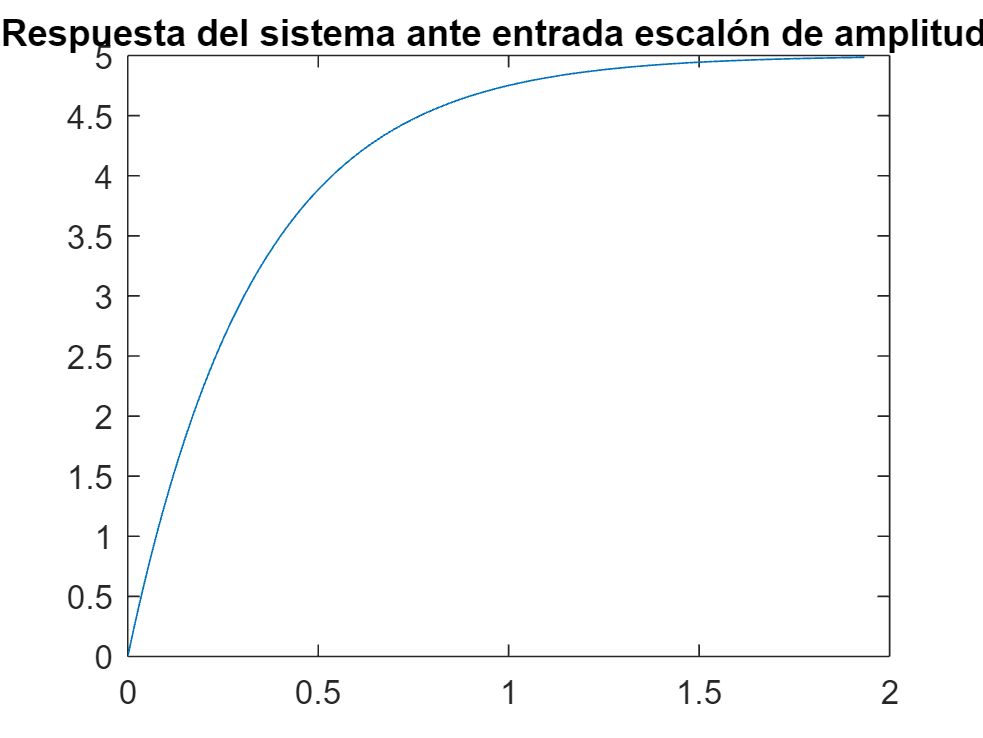

G = tf(3,[1 3]);
[y,t] = step(5*G);
plot(t,y), title('Respuesta del sistema ante entrada escalón de amplitud 5')

**Tarea 5:** Se pide obtener la respuesta ante entrada escalón de amplitud 3 desde $t=0s$ hasta $t=5s$ de la planta definida por la función de transferencia $G\left(s\right)=\frac{2\left(s+1\right)}{\left(s+2+1i\right)\left(s+2-1i\right)}$, y graficarla en color magenta y utilizando un estilo de línea de guiones. 

% Tu código aquí
G=zpk(-1,[-2+1*i -2-1*i],2)

G =
 
     2 (s+1)
  --------------
  (s^2 + 4s + 5)
 
Continuous-time zero/pole/gain model.
Model Properties


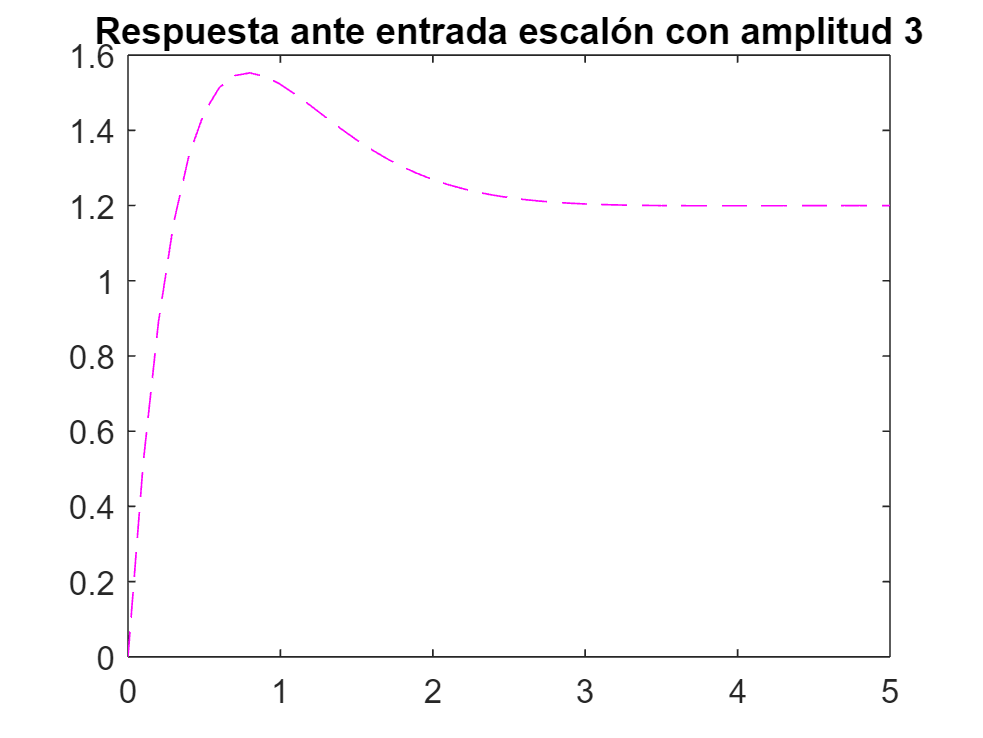

[y,t]= step(3*G,0:0.1:5);
plot(t,y,'m--'),title('Respuesta ante entrada escalón con amplitud 3')

`Resultado esperado:`

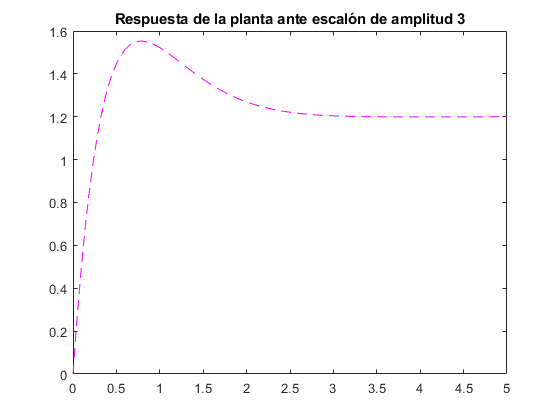

## `2. El impulso unitario`

Por otra parte, en caso de sustituir, en los formatos anteriormente presentados de llamada a la función `step`, el nombre de ésta por `impulse`, se obtendrían los resultados análogos correspondientes a la consideración de una señal de entrada impulso unitario. De este modo:

- `impulse( sys , t )`: simula la respuesta ante entrada impulso del sistema modelado en `sys` (ya sea en descripción externa o interna) hasta el instante de tiempo `t` (opcional). 

Las mismas posibilidades vistas para el comando `step` en cuanto a simulación de diversos sistenas, guardado de la salida de la respuesta, y entradas de distinta amplitud, también están disponibles para `impulse`.

**Tarea 6:** Esta tarea propone la obtención de la respuesta ante impulso unitario del sistema $G\left(s\right)=\frac{2}{s^2 +0\ldotp 3s+2}$ hasta el instante de tiempo $t=50s$.

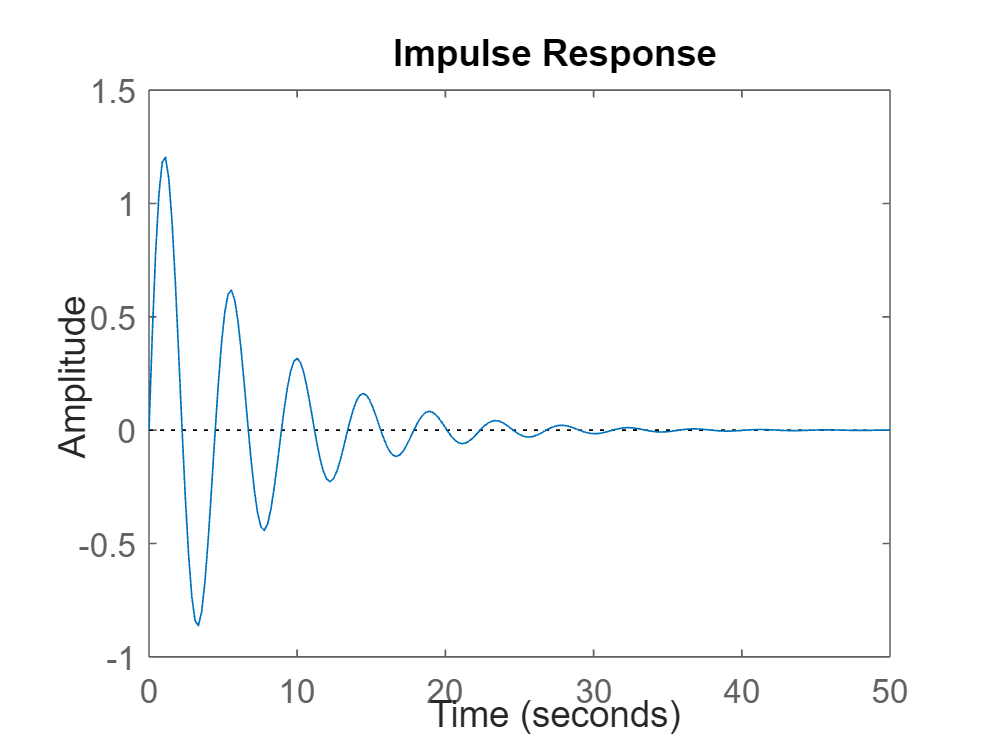

% Tu código aquí
G=tf(2,[1 0.3 2]);
impulse(G,50)

`Resultado esperado:`

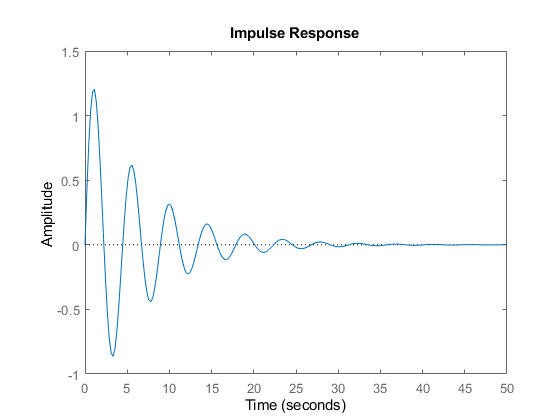

## `3. Rampa/parábola unitaria`

En este caso, MATLAB no nos provee de un comando concreto para la simulación de la respuesta de sistemas ante entrada rampa o parábola unitarias. Pero no está todo perdido, ¡podemos emplear el comando `step` para este fin!

Poniendo el caso de la función de transferencia $G\left(s\right)$ de un sistema, recordamos que la respuesta de este se define como $C\left(s\right)=G\left(s\right)U\left(s\right)$. Sabemos que:

- Entrada escalón unitaria: $u\left(t\right)=1\to U_e \left(s\right)=\frac{1}{s}$.

- Entrada rampa unitaria: $u\left(t\right)=t\to U_r \left(s\right)=\frac{1}{s^2 }$.

- Entrada parábola unitaria $u\left(t\right)=t^2 \to U_p \left(s\right)=\frac{1}{{2s}^3 }$

Por ejemplo, para el caso de la entrada rampa unitaria:


$$C\left(s\right)=G\left(s\right)U_r \left(s\right)=G\left(s\right)\frac{1}{s^2 }=\frac{G\left(s\right)}{s}\frac{1}{s}=\frac{G\left(s\right)}{s}U_e \left(s\right)$$


Por lo que podremos obtener la respuesta rampa unitaria empleando el comando `step` previa multiplicación de la función de transferencai $G\left(s\right)$ por $1/s$:

Para el caso de la parábola unitaria, resultaría: 

**Tarea 7:** Se pide simular la respuesta del sistema $G\left(s\right)=\frac{1}{s^2 +2s+2}\;$ante entrada rampa unitaria hasta el instante $t=10s$, graficando en la misma ventana tanto la entrada en color azul como la respuesta del sistema en color rojo y punteada. Muestra en una leyenda con qué información se corresponde cada línea.

*Pista: *`help legend`* puede serte de ayuda.*

% Tu código aquí
help legend

 legend - Add legend to axes
    This MATLAB function creates a legend with descriptive labels for each
    plotted data series.

    Syntax
      legend
      legend(label1,...,labelN)
      legend(labels)
      legend(subset,___)
      legend(target,___)

      legend(___,'Location',lcn)
      legend(___,'Orientation',ornt)
      legend(___,Name,Value)
      legend(bkgd)
      lgd = legend(___)

      legend(vsbl)
      legend('off')

    Input Arguments
      label1,...,labelN - Labels (as separate arguments)
        character vectors | strings
      <a href="matlab:web('C:\Program Files\MATLAB\R2023b\help\matlab\ref/legend.html#bt6ef_q-1-labels')">labels</a

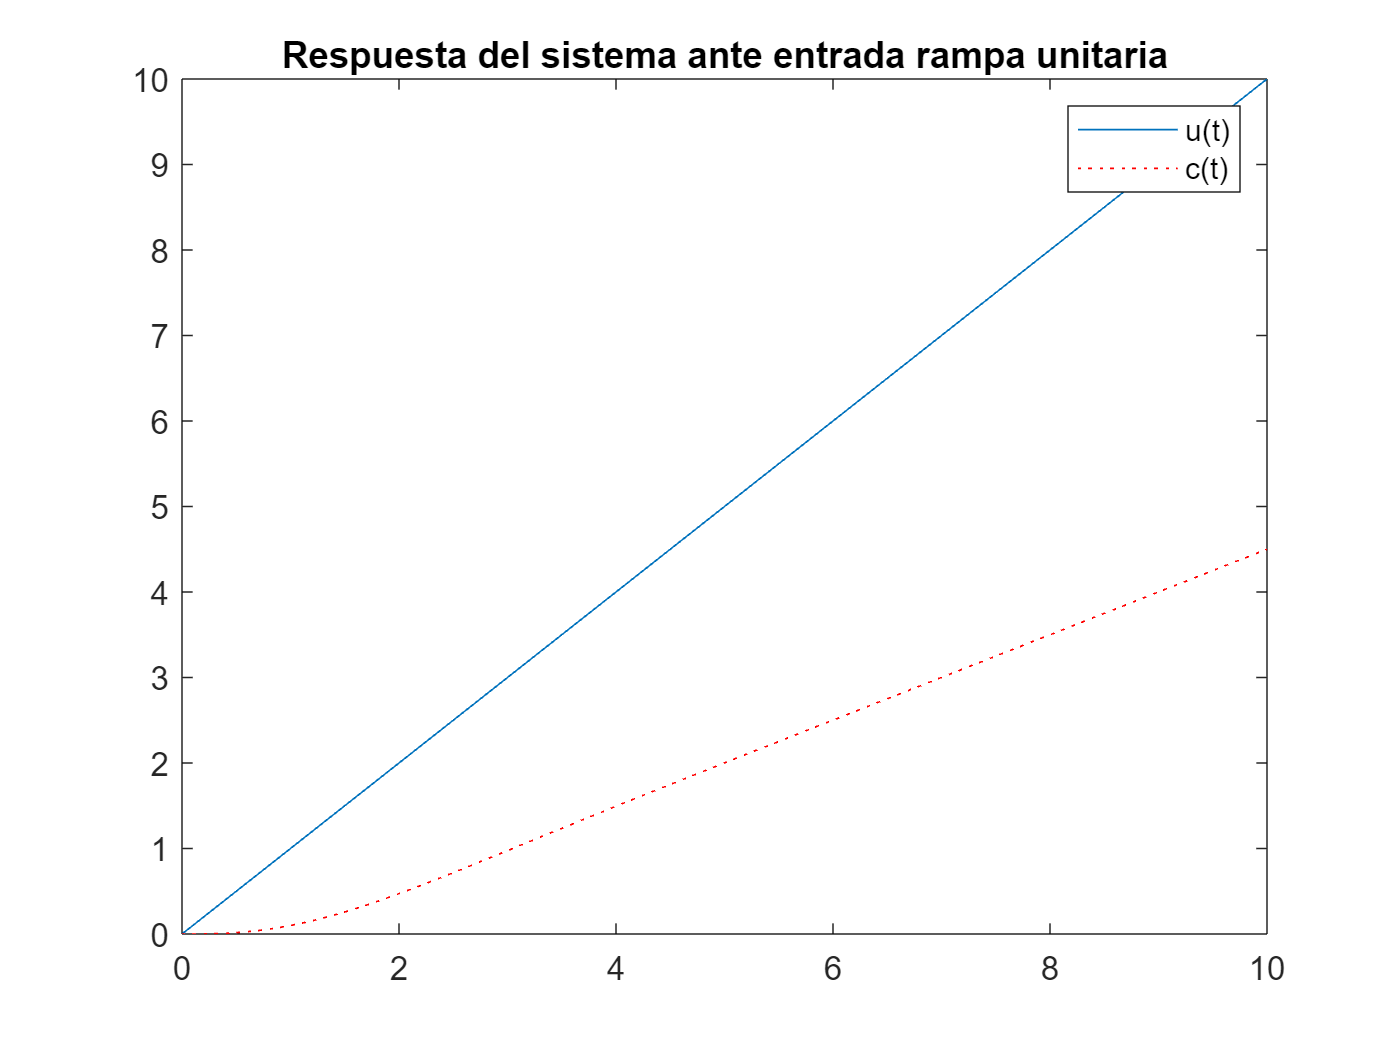

s = tf('s');
G=tf(1,[1 2 2]);
t=0:0.1:10;
y=step(G*(1/s),t);
plot(t,t,t,y,'r:'),title('Respuesta del sistema ante entrada rampa unitaria');
legend ('u(t)','c(t)')

`Resultado esperado:`

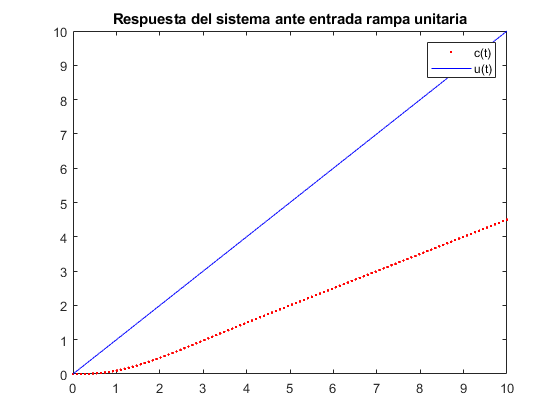

## `4. Creando una señal de entrada arbitraria`

Si queremos analizar la respuesta temporal de nuestro sistema ante una entrada arbitraria distinta de las anteriores, siempre podremos recurrir al comando `lsim`. Su sintaxis es:

`[`$\delta$`y,t,`$\delta$`x] = lsim(G,`$\delta$`u,t,`$\delta$`x0)`

donde:

- $\delta$`y`: respuesta temporal del sistema linealizado para cada uno de los valores del vector `t.`

- `t`: vector de tiempos utilizado para la simulación 

- $\delta$`x`: variables de estado linealizadas calculadas para cada uno de los valores del vector `t `(usado con descripción interna)`.` 

- `G`: sistema dinámico a simular. Para el caso de una descripción interna viene dado por `G=ss(A,B,C,D)`. 

- $\delta$`u`: entrada o actuación, con el mismo número de elementos que el vector `t.` 

- $\delta$`x0`: vector de condiciones iniciales.

Al igual que con el comando step, se puede simular la respuesta de más de un sistema, incluyendo sus modelos a continuación de `G`, incluso especificar su formato. De igual modo, si se llama sin argumentos de salida, se mostrará en una ventana gráfica la respuesta del sistema. 

Ejemplo: La siguiente celda de código muestra gráficamente la respuesta de un sistema ante una entrada escalón de amplitud 3 que se inicia en el instante $t=0s$ y termina en $t=2s$.

inc = 0.01;
t = 0:inc:10;
u = zeros(length(t),1);
u(1:2/inc+1) = 3; % Matlab empieza indexando en 1
G = tf(2,[1 2 1]);
y = lsim(G,u,t);
plot(t,u,t,y); legend('u(t)','c(t)')

**Tarea 8:** Se considera la siguiente función de transferencia que modela un circuito LRC, siendo la entrada el voltaje con el que se alimenta al circuito y la salida la caída de voltaje en el condensador:


$$G_{\textrm{circuito}} \left(s\right)=\frac{2000}{s^2 +20s+2000}$$


Se pide graficar la respuesta del sistema durante 8 segundos ante una entrada escalón de amplitud 5 voltios, recreando un escenario donde se alimenta al circuito desde el instante $t=2s$ hasta $t=4s$.

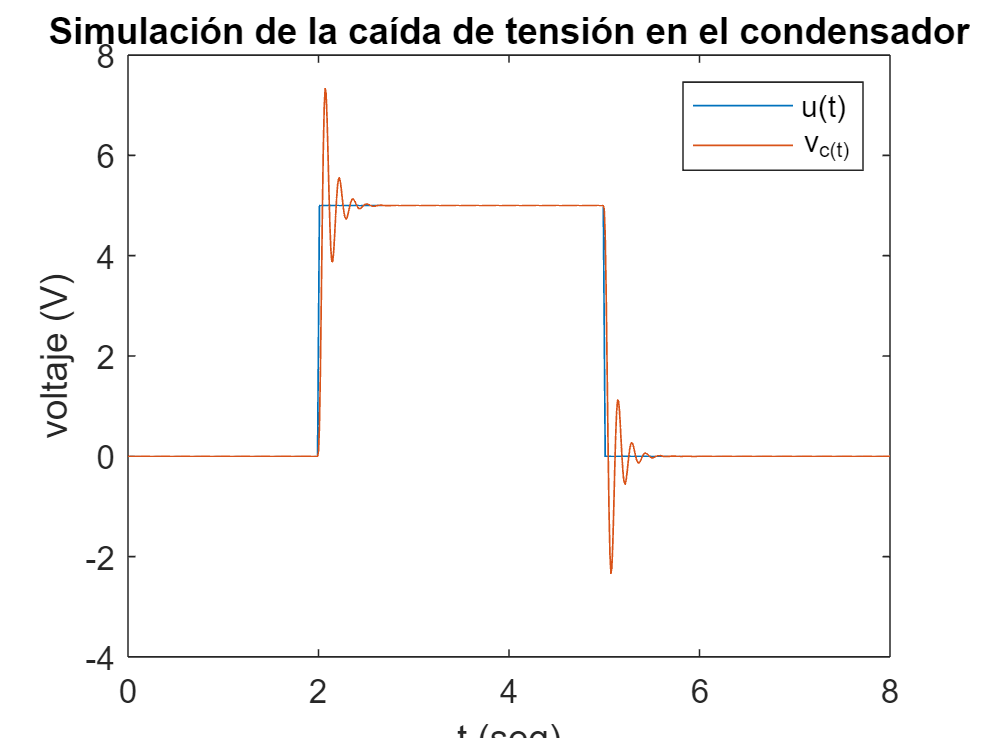

% Tu código aquí
G=tf(2000,[1 20 2000]);
t=0:0.01:8;
u=5*(heaviside(t-2)-heaviside(t-5));
y=lsim(G,u,t);
plot(t,u,t,y),title('Simulación de la caída de tensión en el condensador')
legend('u(t)','v_c(t)')
xlabel('t (seg)');
ylabel('voltaje (V)');

`Resultado esperado:`